# EECE 5644 Intro to Machine Learning Homework #2

## Question 1 (50%)

        The probability density function (pdf) for a 2-dimensional real-valued random vector $\textbf{X}$ is as follows: $p(\textbf{x}) = P(L=0)p(\textbf{x}|L=0) + P(L=1)p(\textbf{x}|L=1)$. Here $L$ is the true class label that indicates which class-label-conditioned pdf generates the data. 

        The class priors are $P\left(L=0\right)=0\ldotp 65\;\textrm{and}\;P\left(L=1\right)=0\ldotp 35$. The class class-conditional pdfs are $p(\textbf{x}|L=0) = w_1g(\textbf{x}|\textbf{m}_{01},\textbf{C}_{01}) + w_2g(\textbf{x}|\textbf{m}_{02},\textbf{C}_{02})$ and $p(\textbf{x}|L=1) = g(\textbf{x}|\textbf{m}_{1},\textbf{C}_{1})$, where $g(\textbf{x}|\textbf{m},\textbf{C})$ is a multivariate Gaussian probability density function with mean vector $\textbf{m}$ and covariance matrix $\textbf{C}
$. The parameters of the class-conditional Gaussian pdfs are: $w_1 = w_2 = 1/2,$ and


$$\textbf{m}_{01} = $$

$$\left\lbrack \begin{array}{c}
3\\
0
\end{array}\right\rbrack$$
 
$$\textbf{C}_{01} = $$

$$\left\lbrack \begin{array}{cc}
2 & 0\\
0 & 1
\end{array}\right\rbrack$$
 
$$\textbf{m}_{02} = $$

$$\left\lbrack \begin{array}{c}
0\\
3
\end{array}\right\rbrack$$

$$\textbf{C}_{02} = $$

$$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right\rbrack$$
 
$$\textbf{m}_{1} = $$

$$\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$$
 
$$\textbf{C}_{1} = $$

$$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


For numerical results requested below, generate 10,000 samples according to this data distribution, keep track of the true class labels for each sample. Save the data and use the same data set in all cases. 

** Part A: **ERM classification using the knowledge of true data pdf:

        1. Specify the minimum expected risk classification rule in the form of a likelihood-ratio test: $\frac{p(\textbf{x}|L=1)}{p(\textbf{x}|L=0)} > \gamma$, where the threshold $\gamma$ is a function of class priors and fixed (nonnegative) loss values for each of the four cases $D=i|L=j$ where $D\in 0,1$ is the decision. 

Here, we are given a likelihood-ratio test for specifiying the minimum-expected risk. Using the formula: 

 $\frac{p(\textbf{x}|L=1)}{p(\textbf{x}|L=0)} > \frac{\lambda_{10}-\lambda_{00}}{\lambda_{01}-\lambda_{11}} \frac{P(L=0)}{P(L=1)}$ , where the value of $\gamma$ is dependent on the terms: $\gamma  = \frac{\lambda_{10}-\lambda_{00}}{\lambda_{01}-\lambda_{11}} \frac{P(L=0)}{P(L=1)}$

Here,  $\lambda_{ij}$ are associated with the loss values of classifying a sample as label $i$ given that the true label was $j$

Thus, for arbitrary nonnegative loss parameters, the decision rule becomes

$\frac{p(\textbf{x}|L=1)}{p(\textbf{x}|L=0)} > \gamma$ $\to \;$Decide 1 $\to D=1$ and  $\frac{p(\textbf{x}|L=1)}{p(\textbf{x}|L=0)} < \gamma$ $\to \;$Decide 0 $\to D=0$

We can further simplify this by assuming $\gamma$ is zero-one loss and taking the log of both sides. Thus, our decision rule becomes:

$\ln{p(\textbf{x}|L=1)} - \ln{p(\textbf{x}|L=0)} > \ln{\gamma}$ $\to \;$Decide 1 $\to D=1$ and  $\ln{p(\textbf{x}|L=1)} - \ln{p(\textbf{x}|L=0)} < \ln{\gamma}$ $\to \;$Decide 0 $\to D=0$

2. Implement this classifier and apply it on the 10,000 sample you generated. Vary the threshold $\gamma$ gradually from $0\;\textrm{to}\;\infty ,$ and for each value of the threshold estimate $P(D=1|L=1; \gamma)$ and $P(D=1|L=0; \gamma)$. Using these paired values, plot an approximation of the ROC curve of the minimum expected risk classifier. Note that at $\gamma =0$ the ROC curve should be at $\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$, and as $\gamma$ increases it should traverse towards $\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \ldotp$ Due to the finite number of samples used to estimate probabilities, your ROC curve approximation should reach this destination value for a finite threshold value. 

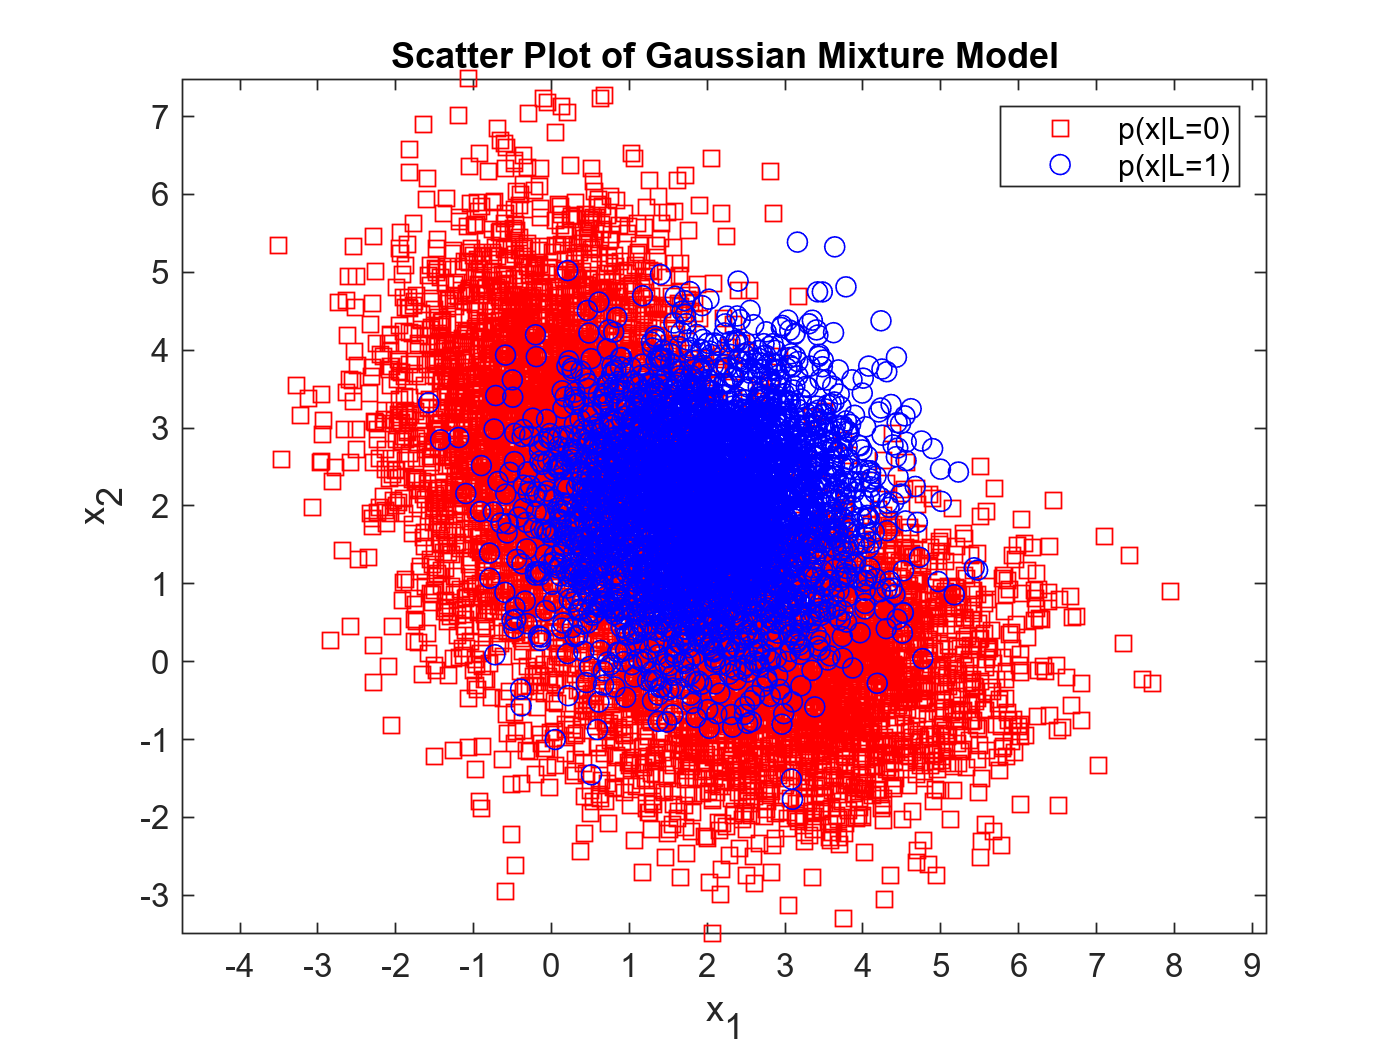

clear all, close all
% Generate 10,000 samples of a 2D Gaussian Mixed Model using Parameters given
N = 10000; % # of samples to generate
C = 2; % # of classes
% Gaussian Mixture Model specifications
m01 = [3 0]; C01 = [2 0; 0 1];
m02 = [0 3]; C02 = [1 0; 0 2];
m1  = [2 2]; C1  = eye(2);
w1  = 1/2;   w2  = 1/2;
PL0 = 0.65;  PL1 = 0.35;
% Create Struct that will store all Parameters specified and pass to
% generation function
gaussParameters.component4label  = [1,1,2]; % Vector indicating # of components for each class
gaussParameters.priors = [PL0, PL1];
gaussParameters.componentWeights = [w1, w2];
gaussParameters.meanVectors = [3,0,2;0,3,2];
covar(:,:,1) = C01;
covar(:,:,2) = C02;
covar(:,:,3) = C1;
gaussParameters.covarMatrices = covar;
[data,classLabels] = HW2gmmData2D(N,gaussParameters); pause(1)

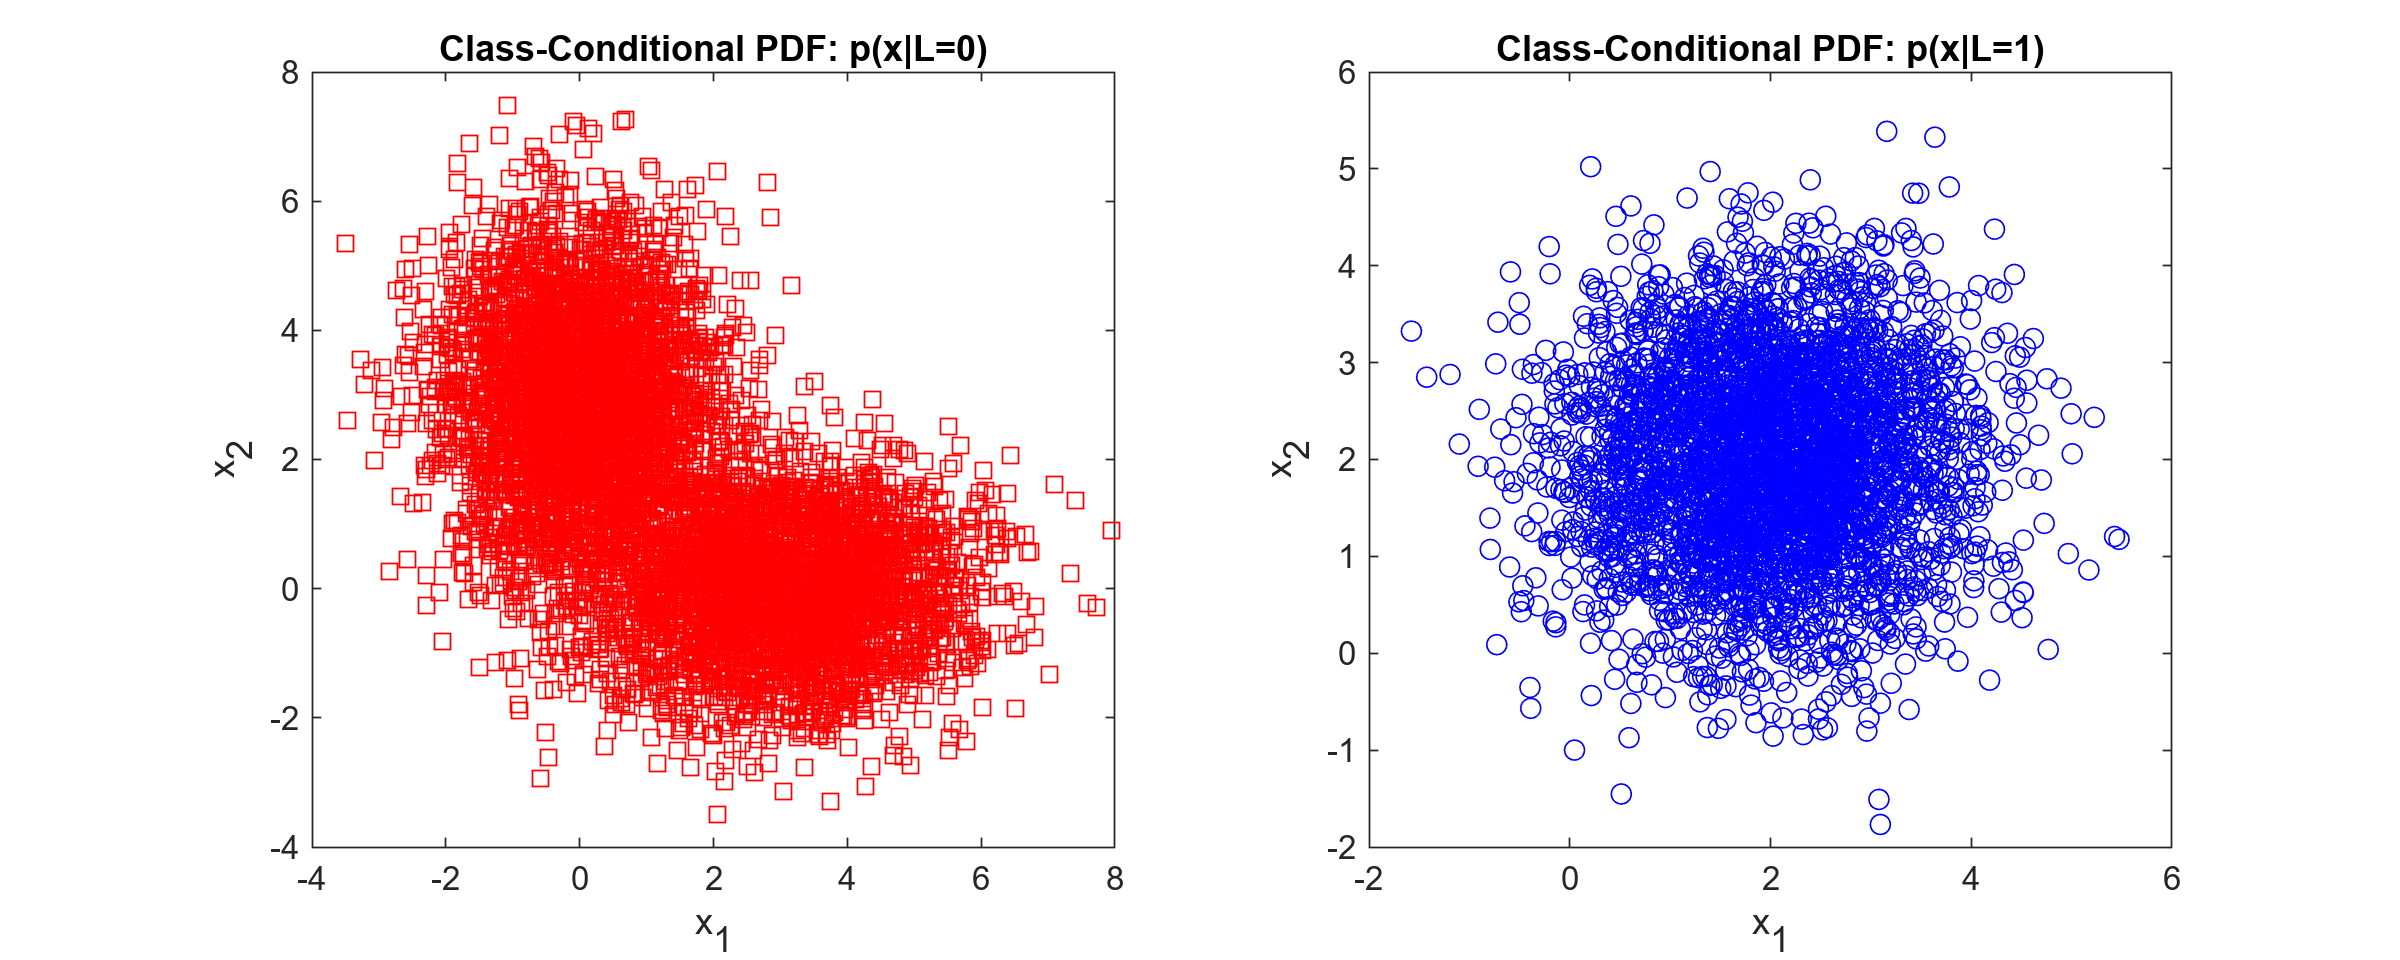

index0 = find(classLabels == 0);
index1 = find(classLabels == 1);
px_L0 = data(:,index0); numL0samples = length(px_L0);
px_L1 = data(:,index1); numL1samples = length(px_L1);
P_l0 = numL0samples/N;
P_l1 = numL1samples/N;
figure('Units','inches','Position',[0,0,10,4]); pause(1)
subplot(1,2,1), plot(px_L0(1,:),px_L0(2,:),'rsquare')
xlabel('x_1'), ylabel('x_2')
title('Class-Conditional PDF: \it{p(x|L=0)}')
subplot(1,2,2), plot(px_L1(1,:),px_L1(2,:),'bo')
xlabel('x_1'), ylabel('x_2')
title('Class-Conditional PDF: \it{p(x|L=1)}')

% Determine ERM decisions for each samples using specified (true) data PDF
gmmLabels = classLabels + 1;
% Two Classes with Priors = [0.65, 0.35]
% Two components for Class 0 with equal weights means 
% Priors = [0.325,0.325,0.35]
gmmPriors = [0.65/2,0.65/2,0.35];
% Use gmdistribution function to generate cell arrays of GMM parameters and
% Class-Conditional pdfs
for l = 1:C
    components{l} = find(gaussParameters.component4label==l);
    classPriors(l,1) = sum(gmmPriors(components{l}));
    compPriors = gmmPriors(components{l})/classPriors(l,1);
    compMeans = gaussParameters.meanVectors(:,components{l})';
    compCovariance = gaussParameters.covarMatrices(:,:,components{l});
    classConditionalPDF{l} = gmdistribution(compMeans,compCovariance,compPriors);
end
% Show Cell array that displays # of Gaussian components for each class
components

components = 1×2 cell array
    {[1 2]}    {[3]}


% Compute discriminant score ln(p(x|L=1))-ln(p(x|L=0))
classConditionalLikelihoods(1,:) = pdf(classConditionalPDF{1},data'); % p(x|L=0)
classConditionalLikelihoods(2,:) = pdf(classConditionalPDF{2},data'); % p(x|L=1)
% Derive a decision boundary log gamma for zero-one loss case
ERMscore = (log(classConditionalLikelihoods(2,:)) - log(classConditionalLikelihoods(1,:)));
% Generate the ROC curves based on true-positive and false-positive values
% derive from true labels
numLabels = [sum(classLabels == 0), sum(classLabels == 1)]

numLabels =         6490        3510


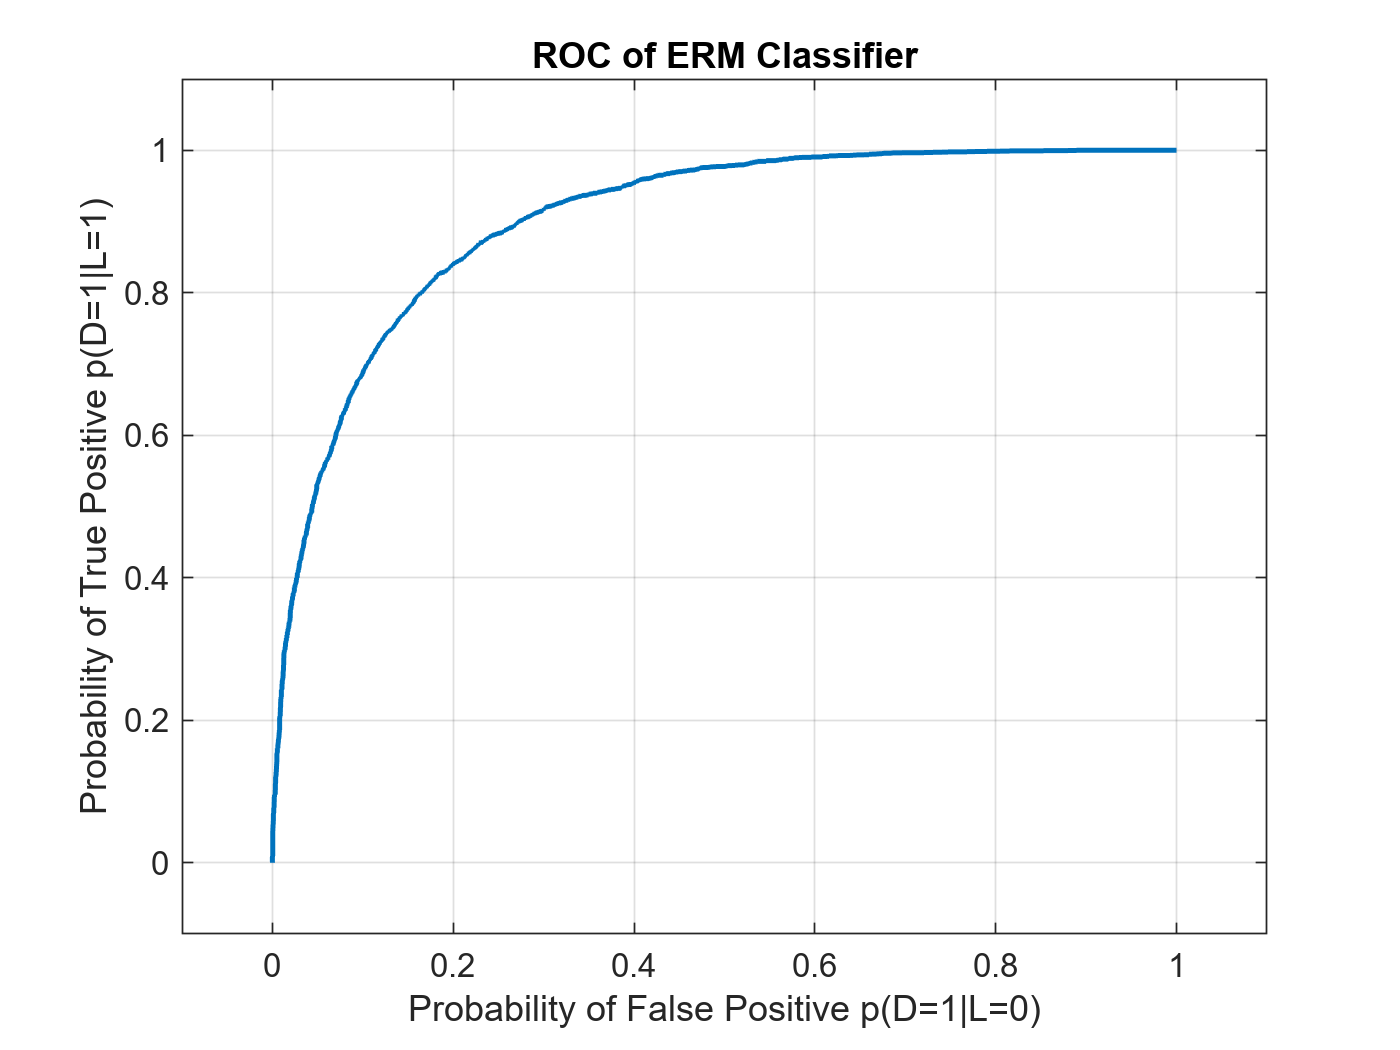

% Sort values of ERMscore to give gradually increase of gamma values to
% compare to log likelihood ratio
gamma_empirical = sort(ERMscore);
% Preallocate space for decision matrix
ERMdecision = zeros(N,N);
for i = 1:length(gamma_empirical)
    g = gamma_empirical(i);
    for j = 1:N
    ERMdecision(i,j) = (ERMscore(j) > g);
    end
end
% Find indices of False Positives from ERMdecision and true classLabels
falsePositive = zeros(N,1); truePositive = zeros(N,1);
for i = 1:N
    falsePositive(i,:) = sum(ERMdecision(i,:) == 1 & classLabels == 0);
    truePositive(i,:) = sum(ERMdecision(i,:) == 1 & classLabels == 1);
end
% Array values for TPs and FPs
falsePositive = falsePositive'./numLabels(1);
truePositive = truePositive'./numLabels(2);
% Plot ROC Curve
figure()
plot(falsePositive,truePositive, 'LineWidth', 1.5), grid on
xlim([-0.1 1.1]), xticks(0:0.2:1), xlabel('Probability of False Positive p(D=1|L=0)')
ylim([-0.1 1.1]), yticks(0:0.2:1), ylabel('Probability of True Positive p(D=1|L=1)')
title('ROC of ERM Classifier')

3. Determine the theoretically optimal threshold value that achieves minimum probability of error, and on the ROC curve, superimpose (using a different color/shape marker) the operating point of this min - $P\left(\textrm{error}\right)$ decision rule by evaluating its two confusion matrix entries needed for its ROC curve point. Estimate the minimum probability of error that is achievable for this data distribution using the dataset and this theoretically optimal threshold. In addition, by evaluating estimated $P(error;\gamma) = P(D=1|L=0;\gamma)P(L=0) + P(D=0|L=1;\gamma)P(L=1)$ values, determine empirically using the dataset a threshold value that minimizes this estimated P(error) value. How does your empirically determined g value that minimizes P(error) compare with the theoretically optimal threshold you compute from priors and loss values?

The optimal threshold can be decided when we consider zero-one loss and include the prior values $P\left(L=0\right)=0\ldotp 65\;\textrm{and}\;P\left(L=1\right)=0\ldotp 35$. Filling in from the arbitrary case we have: 

 $\frac{p(\textbf{x}|L=1)}{p(\textbf{x}|L=0)} > \frac{\lambda_{10}-\lambda_{00}}{\lambda_{01}-\lambda_{11}} \frac{P(L=0)}{P(L=1)}$ , where the value of $\gamma$ is dependent on the terms: $\gamma  = \frac{\lambda_{10}-\lambda_{00}}{\lambda_{01}-\lambda_{11}} \frac{P(L=0)}{P(L=1)} = \frac{0.65}{0.35} = 1.857$

We can further simplify this by taking the log of both sides. Thus, our optimal threshold value is:

$\ln{p(\textbf{x}|L=1)} - \ln{p(\textbf{x}|L=0)} > \ln{(1.857)} \rightarrow \ln{p(\textbf{x}|L=1)} - \ln{p(\textbf{x}|L=0)} > 0.62$ $\to \;$Decide 1 $\to D=1$ and  $\ln{p(\textbf{x}|L=1)} - \ln{p(\textbf{x}|L=0)} < 0.62$ $\to \;$Decide 0 $\to D=0$

% Calculate False Negatives by taking 1 - TP
falseNegative = 1 - truePositive;
% Min P(error;gamma) = P(D = 1|L = 0)P(L = 0) + P(D = 0|L = 1) or 
% FPR*P(L = 0) + FNR*P(L = 1)
Perror_emp = falsePositive*(numLabels(1)/N) + falseNegative*(numLabels(2)/N);
[minPerror_empirical,idx_minPerror_empirical] = min(Perror_emp);
minPerror_empirical

minPerror_empirical = 0.1717

min_gamma_empirical = gamma_empirical(idx_minPerror_empirical)

min_gamma_empirical = 0.6126

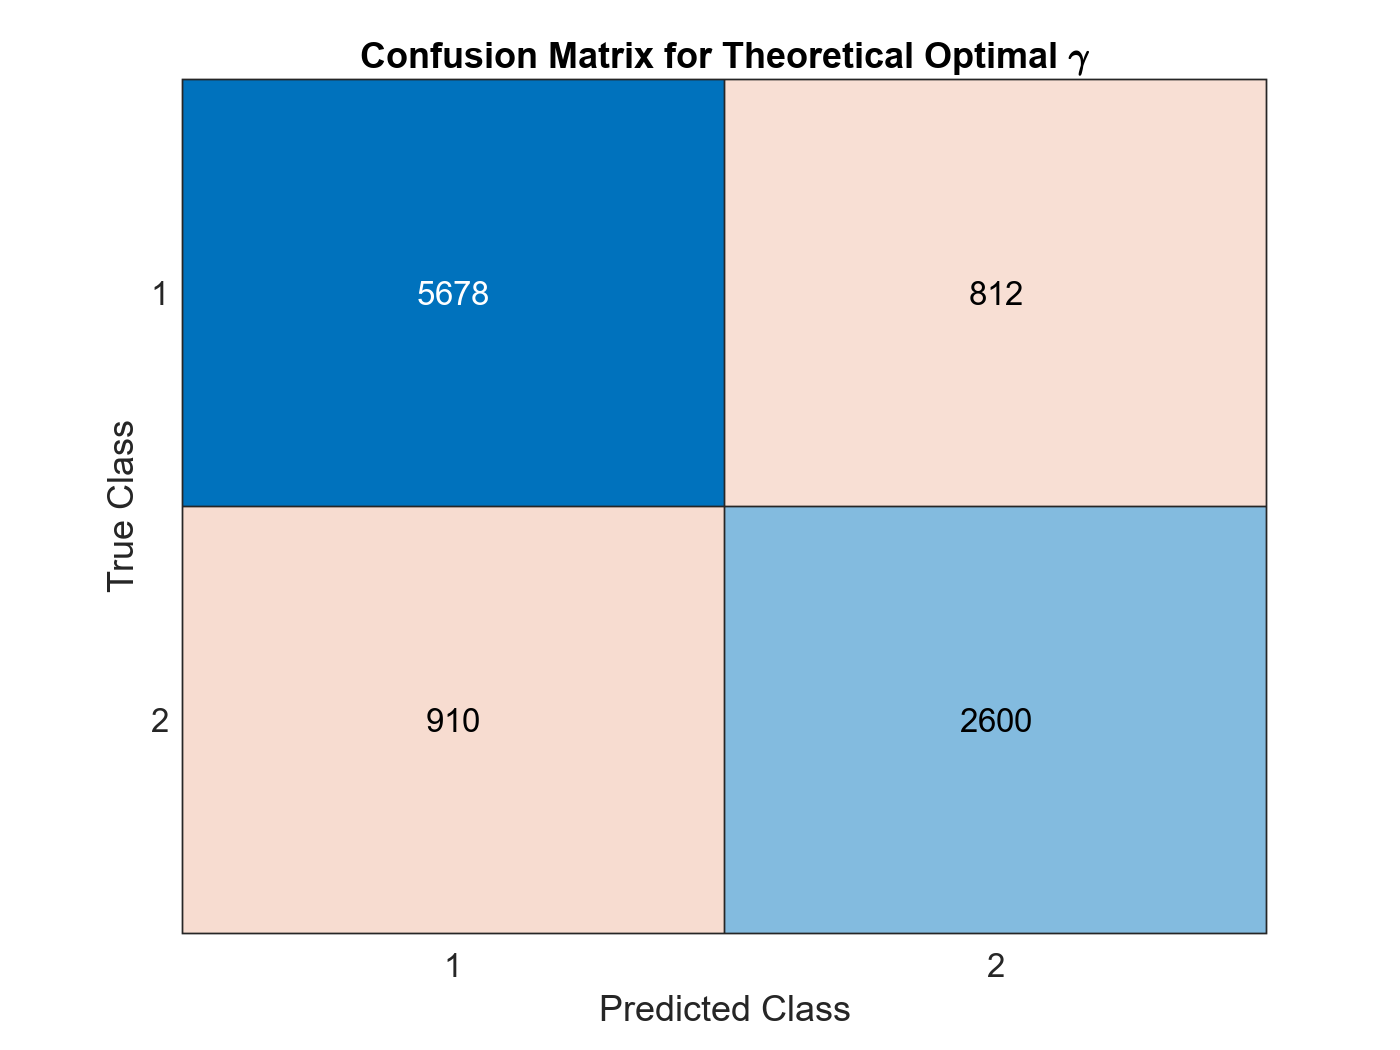

% Theoretical gamma with likelihood ratio test
gamma_theoretical = PL0/PL1; % Theoretical gamma = 1.857
MAPdecision = ERMscore > log(gamma_theoretical);
C = confusionmat(classLabels',MAPdecision');
figure(),confusionchart(C), title('Confusion Matrix for Theoretical Optimal \gamma')

% Use true class labels with new decision scores from theoretical gamma to
% find new TP, TN, FP, and FN rates
% True Positives
idx11 = find(MAPdecision == 1 & classLabels == 1);
TP_theoretical = length(idx11)/numLabels(2)

TP_theoretical = 0.7407

% True Negatives
idx00 = find(MAPdecision == 0 & classLabels == 0);
TN_theoretical = length(idx00)/numLabels(1)

TN_theoretical = 0.8749

% False Positives
idx10 = find(MAPdecision == 1 & classLabels == 0);
FP_theoretical = length(idx10)/numLabels(1)

FP_theoretical = 0.1251

% False Negatives
idx01 = find(MAPdecision == 0 & classLabels == 1);
FN_theoretical = length(idx01)/numLabels(2)

FN_theoretical = 0.2593

Perror_MAP = FP_theoretical*PL0 + FN_theoretical*PL1

Perror_MAP = 0.1721

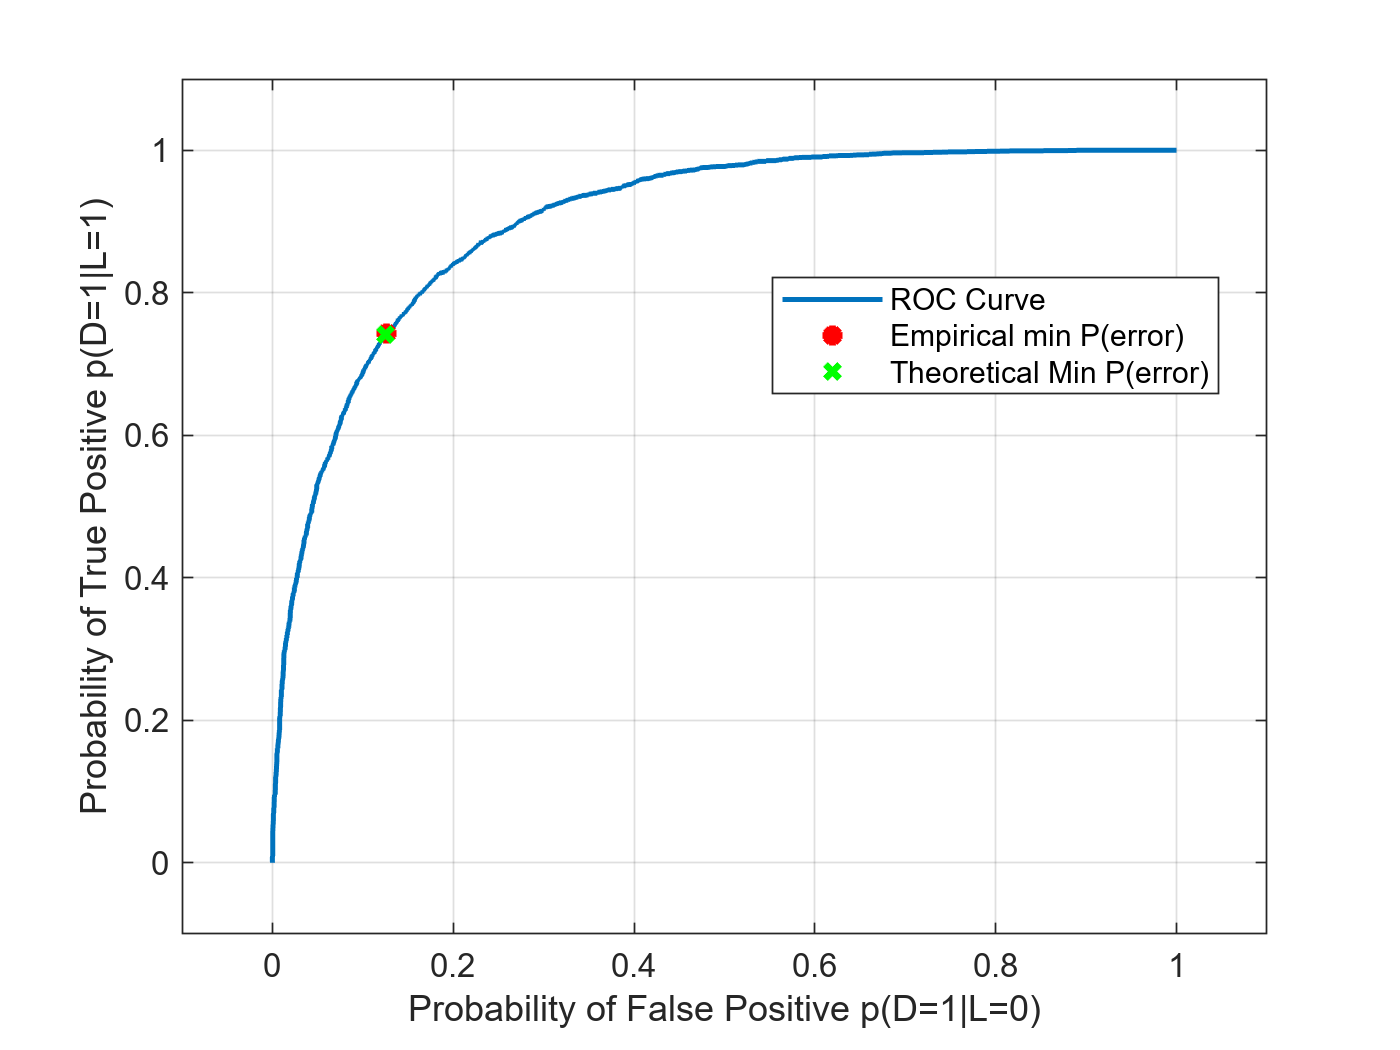

% Plot ROC Curve
figure()
plot(falsePositive,truePositive, 'LineWidth', 1.5), grid on, hold on
plot(falsePositive(idx_minPerror_empirical),truePositive(idx_minPerror_empirical), 'r*', 'LineWidth',2)
plot(FP_theoretical,TP_theoretical, 'gx','LineWidth', 2), pause(1)
xlim([-0.1 1.1]), xticks(0:0.2:1), xlabel('Probability of False Positive p(D=1|L=0)')
ylim([-0.1 1.1]), yticks(0:0.2:1), ylabel('Probability of True Positive p(D=1|L=1)')
legend('ROC Curve','Empirical min P(error)','Theoretical Min P(error)','Location','best')

From my calculations: 

The minimum empirical $P\left(\textrm{error}\right)$ for the ERM classifier was: $\;0\ldotp 1717$

The minimum Empirical $\gamma =0\ldotp 612$

The Theoretical Min $P\left(\textrm{error}\right)$ for the ERM classifier was: $0\ldotp 1721$

The Theoretical value for $\gamma =1\ldotp 857$

**        Part B: **Repeat the same steps as in the previous two cases (draw ROC curve & find threshold that minimizes P(error)), but this time using a Fisher Linear Discriminant Analysis (LDA) based classifier. Using the 10,000 available samples and their labels, estimate the class conditional mean and covariance matrices using sample average estimators. From these estimates, determine the Fisher LDA projection weight vector (via the generalized eigendecomposition of within and between class scatter matrices): $\textbf{w}_{LDA}.$ For the classification rule $\textbf{w}^T_{LDA}\textbf{x}$ compared to a threshold $\tau$, which takes values from $-\infty \;\textrm{to}\;\infty$, plot the ROC curve. Identify the threshold at which the probability of error (based on sample count estimates) is minimized, and mark that operating point on the ROC curve estimate. Discuss how this LDA classifier performs relative to the previous two classifiers. Compare the P(error) achieved by LDA with that of the optimal design.

% Perform LDA on original data and true class labels
% Start by computing the class means
l0 = find(classLabels == 0);
l1 = find(classLabels == 1);
classConditionalMean1 = mean(data(:,l0)')'

classConditionalMean1 =     1.4762
    1.4775


classConditionalMean2 = mean(data(:,l1)')'

classConditionalMean2 =     2.0002
    1.9963


% Covariance matrices for each class
S0 = cov(data(:,l0)')

S0 =     3.7944   -2.2385
   -2.2385    3.7149


S1 = cov(data(:,l1)')

S1 =     1.0095    0.0173
    0.0173    1.0029


% Compute Within-Class Scatter Matrix
Sw = S0 + S1

Sw =     4.8039   -2.2211
   -2.2211    4.7178


% Compute Between-Class Scatter Matrix
Sb = (classConditionalMean1-classConditionalMean2)*(classConditionalMean1-classConditionalMean2)'

Sb =     0.2745    0.2718
    0.2718    0.2691


% Compute the LDA projection
invSw = inv(Sw);
invSwxSb = Sw\Sb

invSwxSb =     0.1071    0.1060
    0.1080    0.1070


% Take the eigenvalues of Sw^-1Sb to derive the projection vector
[V,D] = eig(invSwxSb);
wLDA = V(:,1)

wLDA =     0.7040
    0.7102


After estimating class conditional means and covariance matrices using sample average estimators, I've determined that the Fisher LDA projection weight vector $\textbf{w}^T_{LDA}$ is:


$$\textbf{w}^T_{LDA} =$$

$$\left\lbrack \begin{array}{c}
0\ldotp 7040\\
0\ldotp 7102
\end{array}\right\rbrack$$


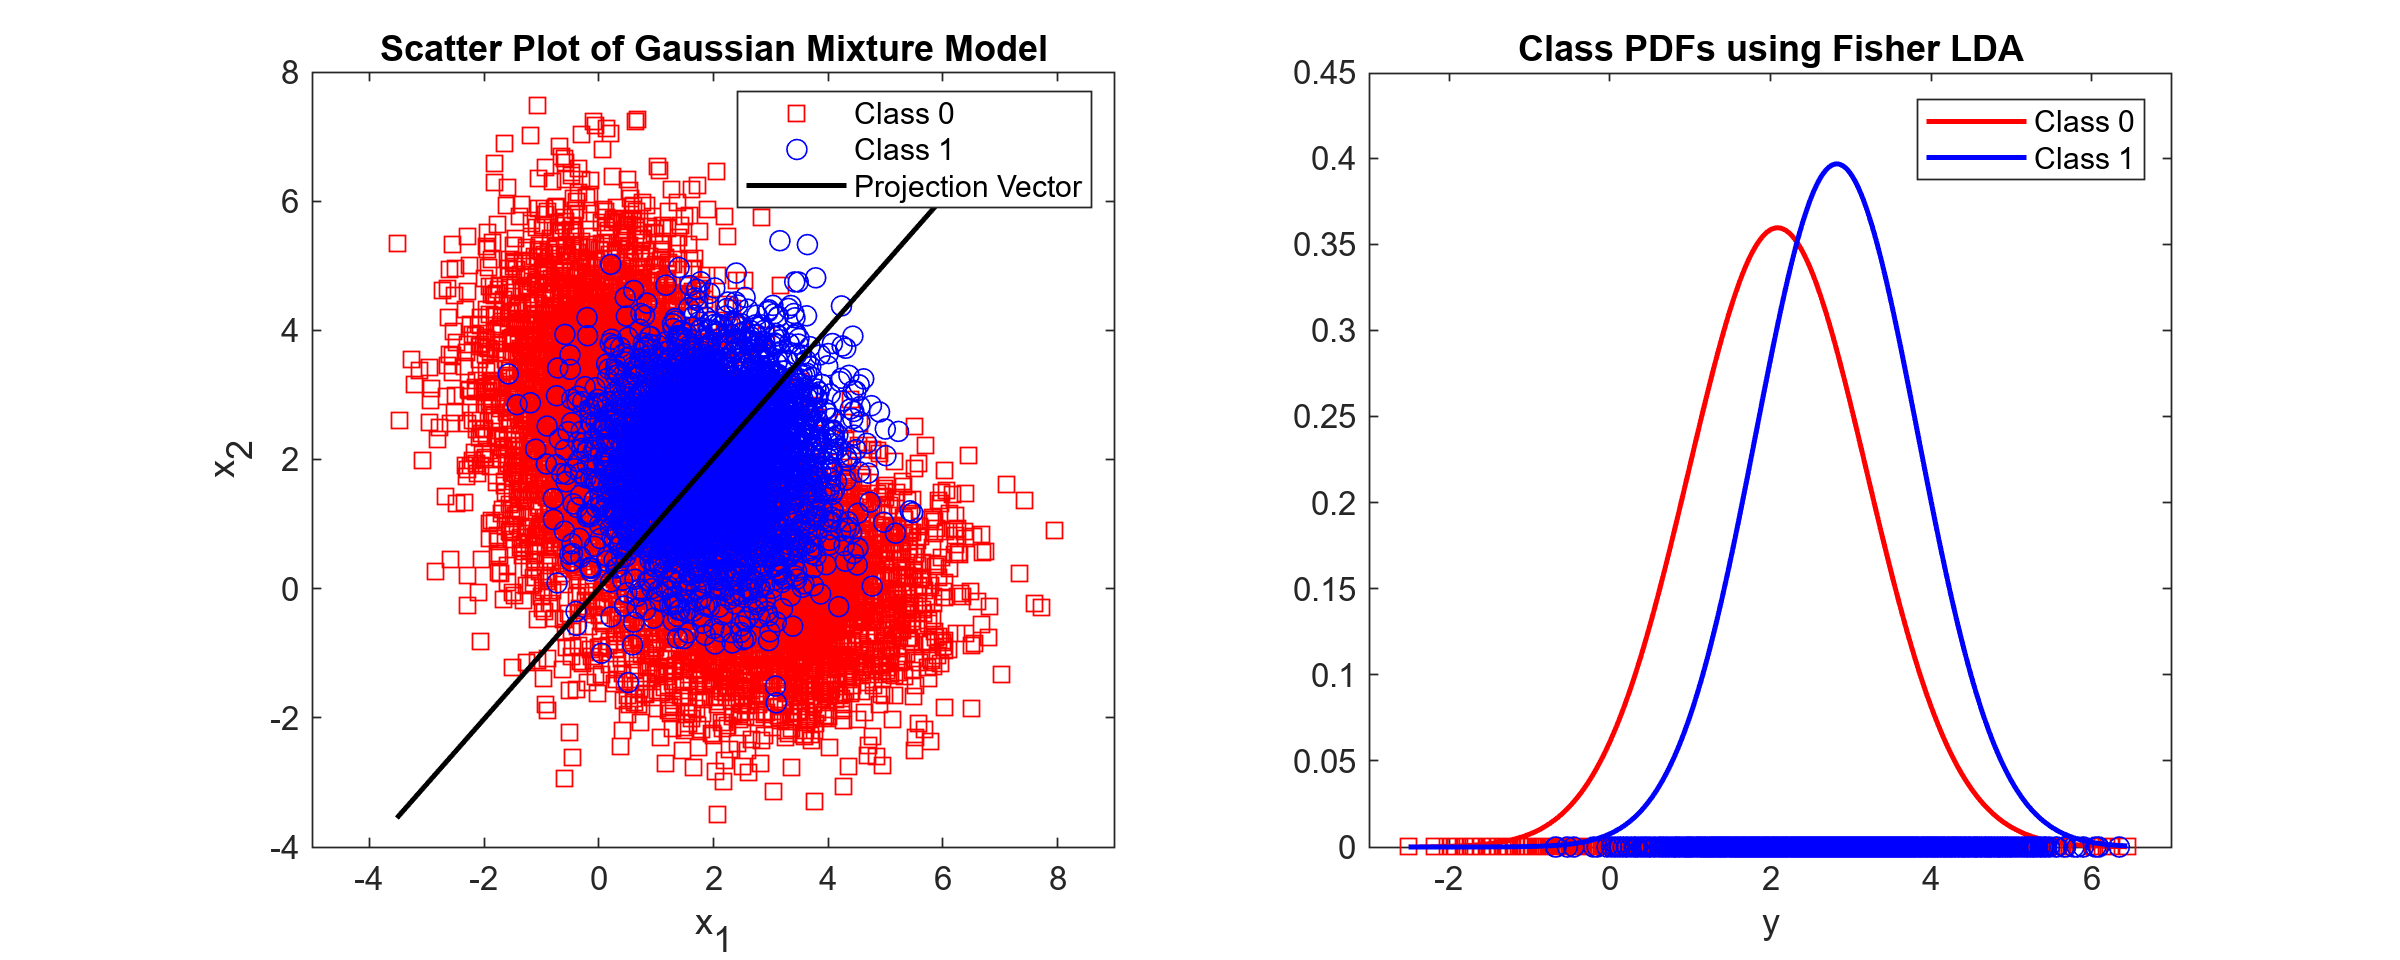

LDAscore = wLDA'*data; % Scalar y the reduced dimension of 2D x-data
% Derive projection vectors and plot with original scatter plot
t = -5:0.5:10;
line_x = t.*wLDA(1,:);
line_y = t.*wLDA(2,:);
% find where each labeled data is projected
y1 = LDAscore(l0); y2 = LDAscore(l1);
class0.data = wLDA'*data(:,l0);
class1.data = wLDA'*data(:,l1);
% Project data samples along the projection axes limits
minY = min([min(class0.data),min(class1.data)]);
maxY = max([max(class0.data),max(class1.data)]);
y_wLDA = minY:0.01:maxY;
% Find parameters of Class 0 in terms of wLDA
class0.mu = mean(class0.data);
class0.sigma = std(class0.data);
class0.pdf = mvnpdf(y_wLDA',class0.mu,class0.sigma);
% Find parameters of Class 1 in terms of wLDA
class1.mu = mean(class1.data);
class1.sigma = std(class1.data);
class1.pdf = mvnpdf(y_wLDA',class1.mu,class1.sigma);
% Plot LDA projection vector and Original Scatter Plot of GMM
figure('Units','inches','Position',[0,0,10,4]);
subplot(1,2,1)
plot(data(1,l0), data(2,l0),'rsquare'), hold on
plot(data(1,l1), data(2,l1),'bo'), pause(1)
plot(line_x,line_y,'k-','LineWidth',1.5)
xlim([-5 9]), hold off
xlabel('x_1'), ylabel('x_2'), title('Scatter Plot of Gaussian Mixture Model')
legend('Class 0','Class 1','Projection Vector','Location','best')
subplot(1,2,2)
plot(y1,zeros(1,numLabels(1)),'rsquare'); hold on;
plot(y_wLDA,class0.pdf,'r','LineWidth',1.5)
plot(y2,zeros(1,numLabels(2)),'bo')
plot(y_wLDA,class1.pdf,'b','LineWidth',1.5)
ylim([0 0.45]), xlim([-3 7]), ylabel('p(x|L=i)')
xlabel('y'), title('Class PDFs using Fisher LDA'), legend('','Class 0','','Class 1')

% Compare wLDA'*x with threshold tau varied from -Inf to Inf and plot ROC
tau = sort(LDAscore);
% Preallocate space for decision matrix
LDAdecision = zeros(N,N);
for i = 1:length(tau)
    t = tau(i);
    for j = 1:N
    LDAdecision(i,j) = (LDAscore(j) > t);
    end
end
% Find indices of False Positives from ERMdecision and true classLabels
FP_LDA = zeros(N,1); TP_LDA = zeros(N,1);
for i = 1:N
    FP_LDA(i,:) = sum(LDAdecision(i,:) == 1 & classLabels == 0);
    TP_LDA(i,:) = sum(LDAdecision(i,:) == 1 & classLabels == 1);
end
% Array values for TPs and FPs
FP_LDA = FP_LDA'./numLabels(1);
TP_LDA = TP_LDA'./numLabels(2);
% Calculate FN_LDA by taking 1 - TP_LDA
FN_LDA = 1 - TP_LDA;
% Min P(error;gamma) = P(D = 1|L = 0)P(L = 0) + P(D = 0|L = 1) or 
% FPR*P(L = 0) + FNR*P(L = 1)
Perror_lda = FP_LDA*(numLabels(1)/N) + FN_LDA*(numLabels(2)/N);
[minPerror_lda,idx_minPerror_lda] = min(Perror_lda);
minPerror_lda

minPerror_lda = 0.3413

min_tau_lda = tau(idx_minPerror_lda)

min_tau_lda = 3.5218

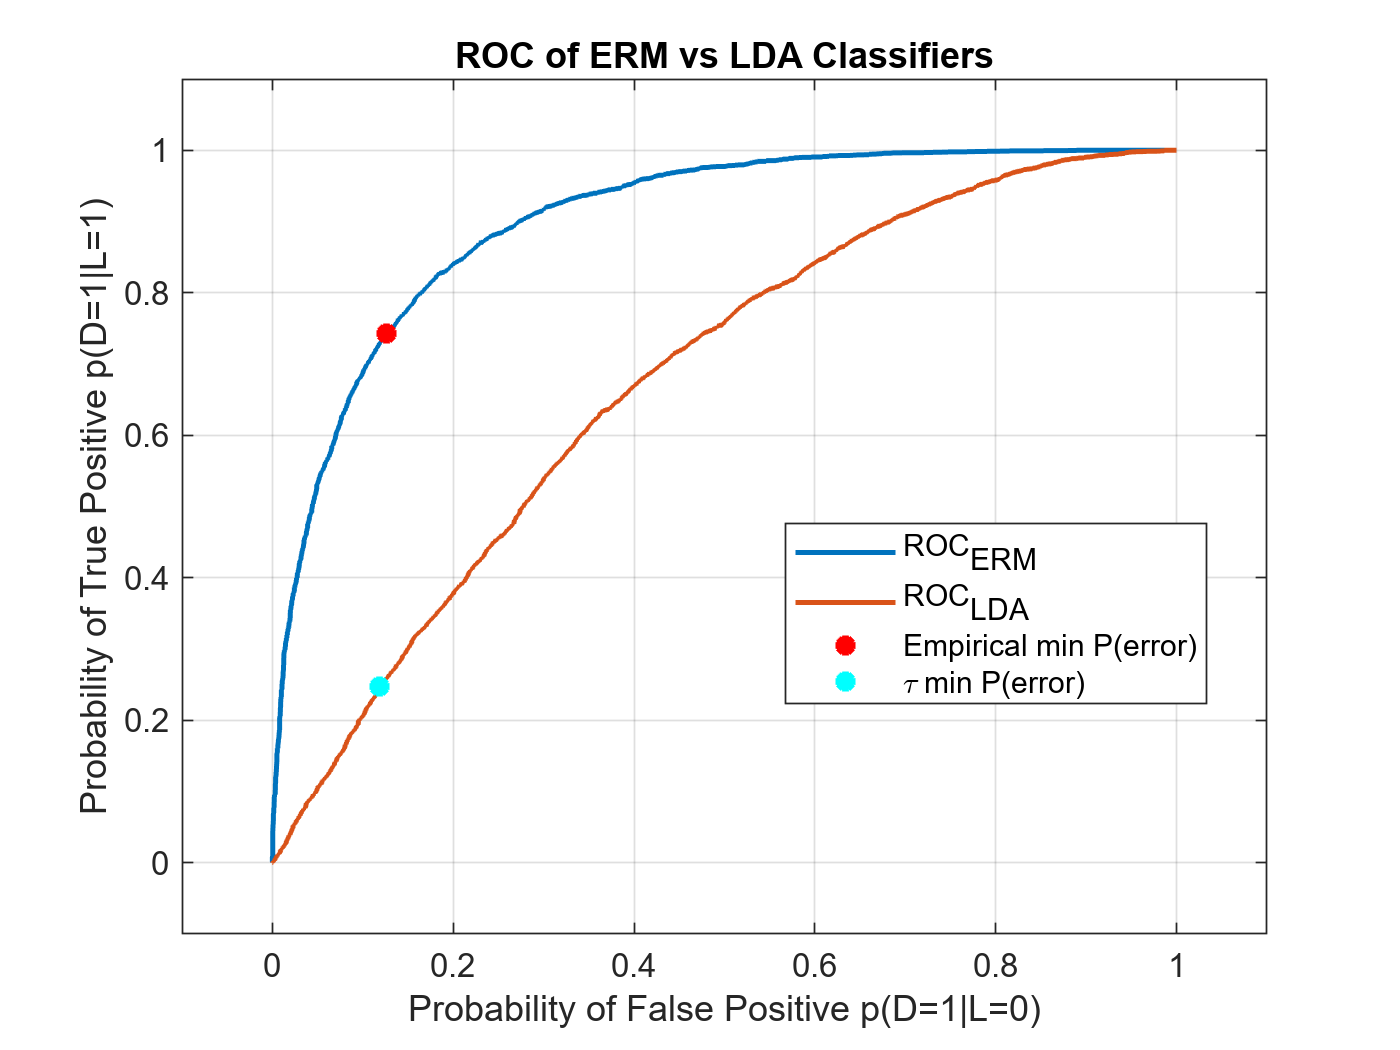

% Plot ROC Curve
figure()
plot(falsePositive,truePositive, 'LineWidth', 1.5), grid on, hold on
plot(FP_LDA,TP_LDA,'LineWidth',1.5),
plot(falsePositive(idx_minPerror_empirical),truePositive(idx_minPerror_empirical), 'r*', 'LineWidth',2)
plot(FP_LDA(idx_minPerror_lda),TP_LDA(idx_minPerror_lda), 'c*', 'LineWidth',2), hold off
xlim([-0.1 1.1]), xticks(0:0.2:1), xlabel('Probability of False Positive p(D=1|L=0)')
ylim([-0.1 1.1]), yticks(0:0.2:1), ylabel('Probability of True Positive p(D=1|L=1)')
legend('ROC_{ERM}','ROC_{LDA}','Empirical min P(error)','\tau min P(error)','Location','best')
title('ROC of ERM vs LDA Classifiers')

The plot of the ROC curve for the LDA classifier is shown above along with the min $P\left(\textrm{error}\right)$ for the threshold value of $\tau$

The calculated Min $P\left(\textrm{error}\right)$ for the LDA classifier was: $0\ldotp 3413$ with the corresponding value for $\tau =3\ldotp 522$

It can be seen from the plot, that the performance for the LDA classifier is indeed worse than the ERM classifier. This matches the expectation for the performance of the LDA classifier, as it's only appeal is the aspect of dimension-reduction, but does not lead to a better classification rate

When comparing the min $P\left(\textrm{error}\right)$ value for the LDA classifier, $\min \;P\left(\textrm{error}\right)=0\ldotp 3413,$ to the optimal value calculated in the previous part, $\textrm{optimal}\;\min \;P\left(\textrm{error}\right)=0\ldotp 1721$, the LDA classifier performance was twice that of the optimal value, which conveys this point that the LDA classifier can be appealing for its dimensionality-reduction features, but however, it is still not a better classifier than a Bayes' minimal expected risk classifier. 

        *Note: When finding the Fisher LDA projection matrix, do not be concerned about the difference in the class priors. When determining the between-class and within-class scatter matrices, use equal weights for the class means and covariances, like we did in class. You could argue for a weighted approach, but in this case the model mismatch is a more serious issue to be concerned about.*

## Question 2 (50%)

        A 3-dimensional random vector $\textbf{X}$ takes values from a mixture of four Gaussians. One of these Gaussians represent the class-conditional pdf for class 1, and another Gaussian represents the class-conditional pdf for class 2. Class 3 data originates from a mixture of the remaining 2 Gaussian components with *equal weights*. For this setting where labels $L \in \{1,2,3\}$, pick your own class-conditional pdfs $p(\textbf{x}|L=j), j \in \{1,2,3\}$ as described. Try to approximately set the distances between means of pairs of Gaussians to twice the average standard deviation of the Gaussian components, so that there is some significant overlap between class-conditional pdfs. Set class priors to 0.3,0.3,0.4.

Known and Choosen Parameters: 


$$\textbf{m}_{1} = $$

$$\left\lbrack \begin{array}{c}
2\\
0\\
0
\end{array}\right\rbrack$$
 
$$\textbf{C}_{1} = $$

$$\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right\rbrack$$
 
$$\textbf{m}_{2} = $$

$$\left\lbrack \begin{array}{c}
0\\
2\\
0
\end{array}\right\rbrack$$
 
$$\textbf{C}_{2} = $$

$$\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right\rbrack$$
  
$$\textbf{m}_{31} = $$

$$\left\lbrack \begin{array}{c}
0\\
0\\
-2
\end{array}\right\rbrack$$
  
$$\textbf{C}_{31} = $$

$$\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right\rbrack$$
  
$$\textbf{m}_{32} = $$

$$\left\lbrack \begin{array}{c}
0\\
0\\
2
\end{array}\right\rbrack$$
 
$$\textbf{C}_{32} = $$

$$\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right\rbrack$$
 


$$P\left(L=1\right)=0\ldotp 3,\;P\left(L=2\right)=0\ldotp 3,\;P\left(L=3\right)=0\ldotp 4$$


$p(\textbf{x}|L=1) = g(\textbf{x}|\textbf{m}_{1},\textbf{C}_{1})$, $p(\textbf{x}|L=2) = g(\textbf{x}|\textbf{m}_{2},\textbf{C}_{2})$, and $p(\textbf{x}|L=3) = w_1g(\textbf{x}|\textbf{m}_{31},\textbf{C}_{31}) + w_2g(\textbf{x}|\textbf{m}_{32},\textbf{C}_{32})$, 

        where $g(\textbf{x}|\textbf{m},\textbf{C})$ is a multivariate Gaussian probability density function with mean vector $\textbf{m}$ and covariance matrix $\textbf{C}
$ and $w_1 =w_2 =1/2$

        **Part A: **Minimum probability of error classification (0-1 loss, also referred to as Bayes Decision rule or MAP classifier).

- Generate 10,000 samples from this data distribution and keep track of the true labels of each sample. 

- Specifiy the decision rule that achieves minimum probability of error (i.e., use 0-1 loss), implement this classifier with the true data distribution knowledge, classify the 10,000 samples and count the samples corresponding to each decision-label pair to empirically estimate the confusion matrix whose entries are $P(D=i|L=j)$ for $i,j\in \left\lbrace 1,2,3\right\rbrace \ldotp$

- Provide a visualization of the data (scatter-plot in 3-dimensional space), and for each sample indicate the true class label with a different marker shape (dot, circle, triangle, square) and whether it was correctly (green) or incorrectly (red) classified with a different marker color as indicated in parentheses.

For generating the appropriate amount of separation between pairs of means for the Gaussian components, I've choosen a constant covariance matrix for all the Gaussian components. This results in the avg covariance matrix: 

$\Sigma_{\textrm{avg}} =\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 2
\end{array}\right\rbrack$ then taking the square root of the diagonal to get the average standard deviation $\to \sigma =\sqrt{2}$

The distance between pairs of means should be twice the value calculated for the average standard deviation, so: $d=2\sqrt{2}$

Using this distance value,  I chose to set each gaussian component's mean at a single vector point for each XYZ axis. 

So, for example distance between  $\textbf{m}_{1} = $$\left\lbrack \begin{array}{c}
2\\
0\\
0
\end{array}\right\rbrack$ and $\textbf{m}_{2} = $$\left\lbrack \begin{array}{c}
0\\
2\\
0
\end{array}\right\rbrack$ is:


$$d=\sqrt{{\left(x_2 -x_1 \right)}^2 +{\left(y_2 -y_1 \right)}^2 +{\left(z_2 -z_1 \right)}^2 }=\sqrt{{\left(0-2\right)}^2 +{\left(2-0\right)}^2 +{\left(0-0\right)}^2 }=\sqrt{4}=2\sqrt{2}\;$$


Thus, each gaussian compont choosen has a distance of $2\sqrt{2}$ between pairs of means

For the decision rule that achieves the min $P\left(\textrm{error}\right)$ using zero-one loss, we wish to choose the class label $i$ which minimizes the loss/risk for the choosen class label. Thus the ERM classification rule can be derived as:


$$D(\textbf{x}) = \underset{i\in\{1,2,3\}}{argmin}\sum_{j=1}^{3}\lambda_{ij}p(\textbf{x}|L=j)P(L=j)$$


where the term $\lambda_{\textrm{ij}}$ represents the ${\left(i,j\right)}^{\textrm{th}}$ element of the 0-1 loss matrix, and $p(\textbf{x}|L=j)P(L=j)$ are the class-conditional likelihoods and priors for the given class label $j$. 

Using the fact that we have 0-1 loss, we form the loss matrix $\to \;\Lambda =\left\lbrack \begin{array}{ccc}
0 & 1 & 1\\
1 & 0 & 1\\
1 & 1 & 0
\end{array}\right\rbrack$ , a diagonal matrix of the Priors and column vectors of the class-conditional likelihoods to convert the above decision rule into matrix form: 


$$D(\textbf{x}) = $$

$$\Lambda \left\lbrack \begin{array}{ccc}
P\left(L=1\right) & 0 & 0\\
0 & P\left(L=2\right) & 0\\
0 & 0 & P\left(L=3\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p\left(x|L=1\right)\\
p\left(x|L=2\right)\\
p\left(x|L=3\right)
\end{array}\right\rbrack$$


and thus, the min $P\left(\textrm{error}\right)$ will be associated with the min conditional risk for this classification. 

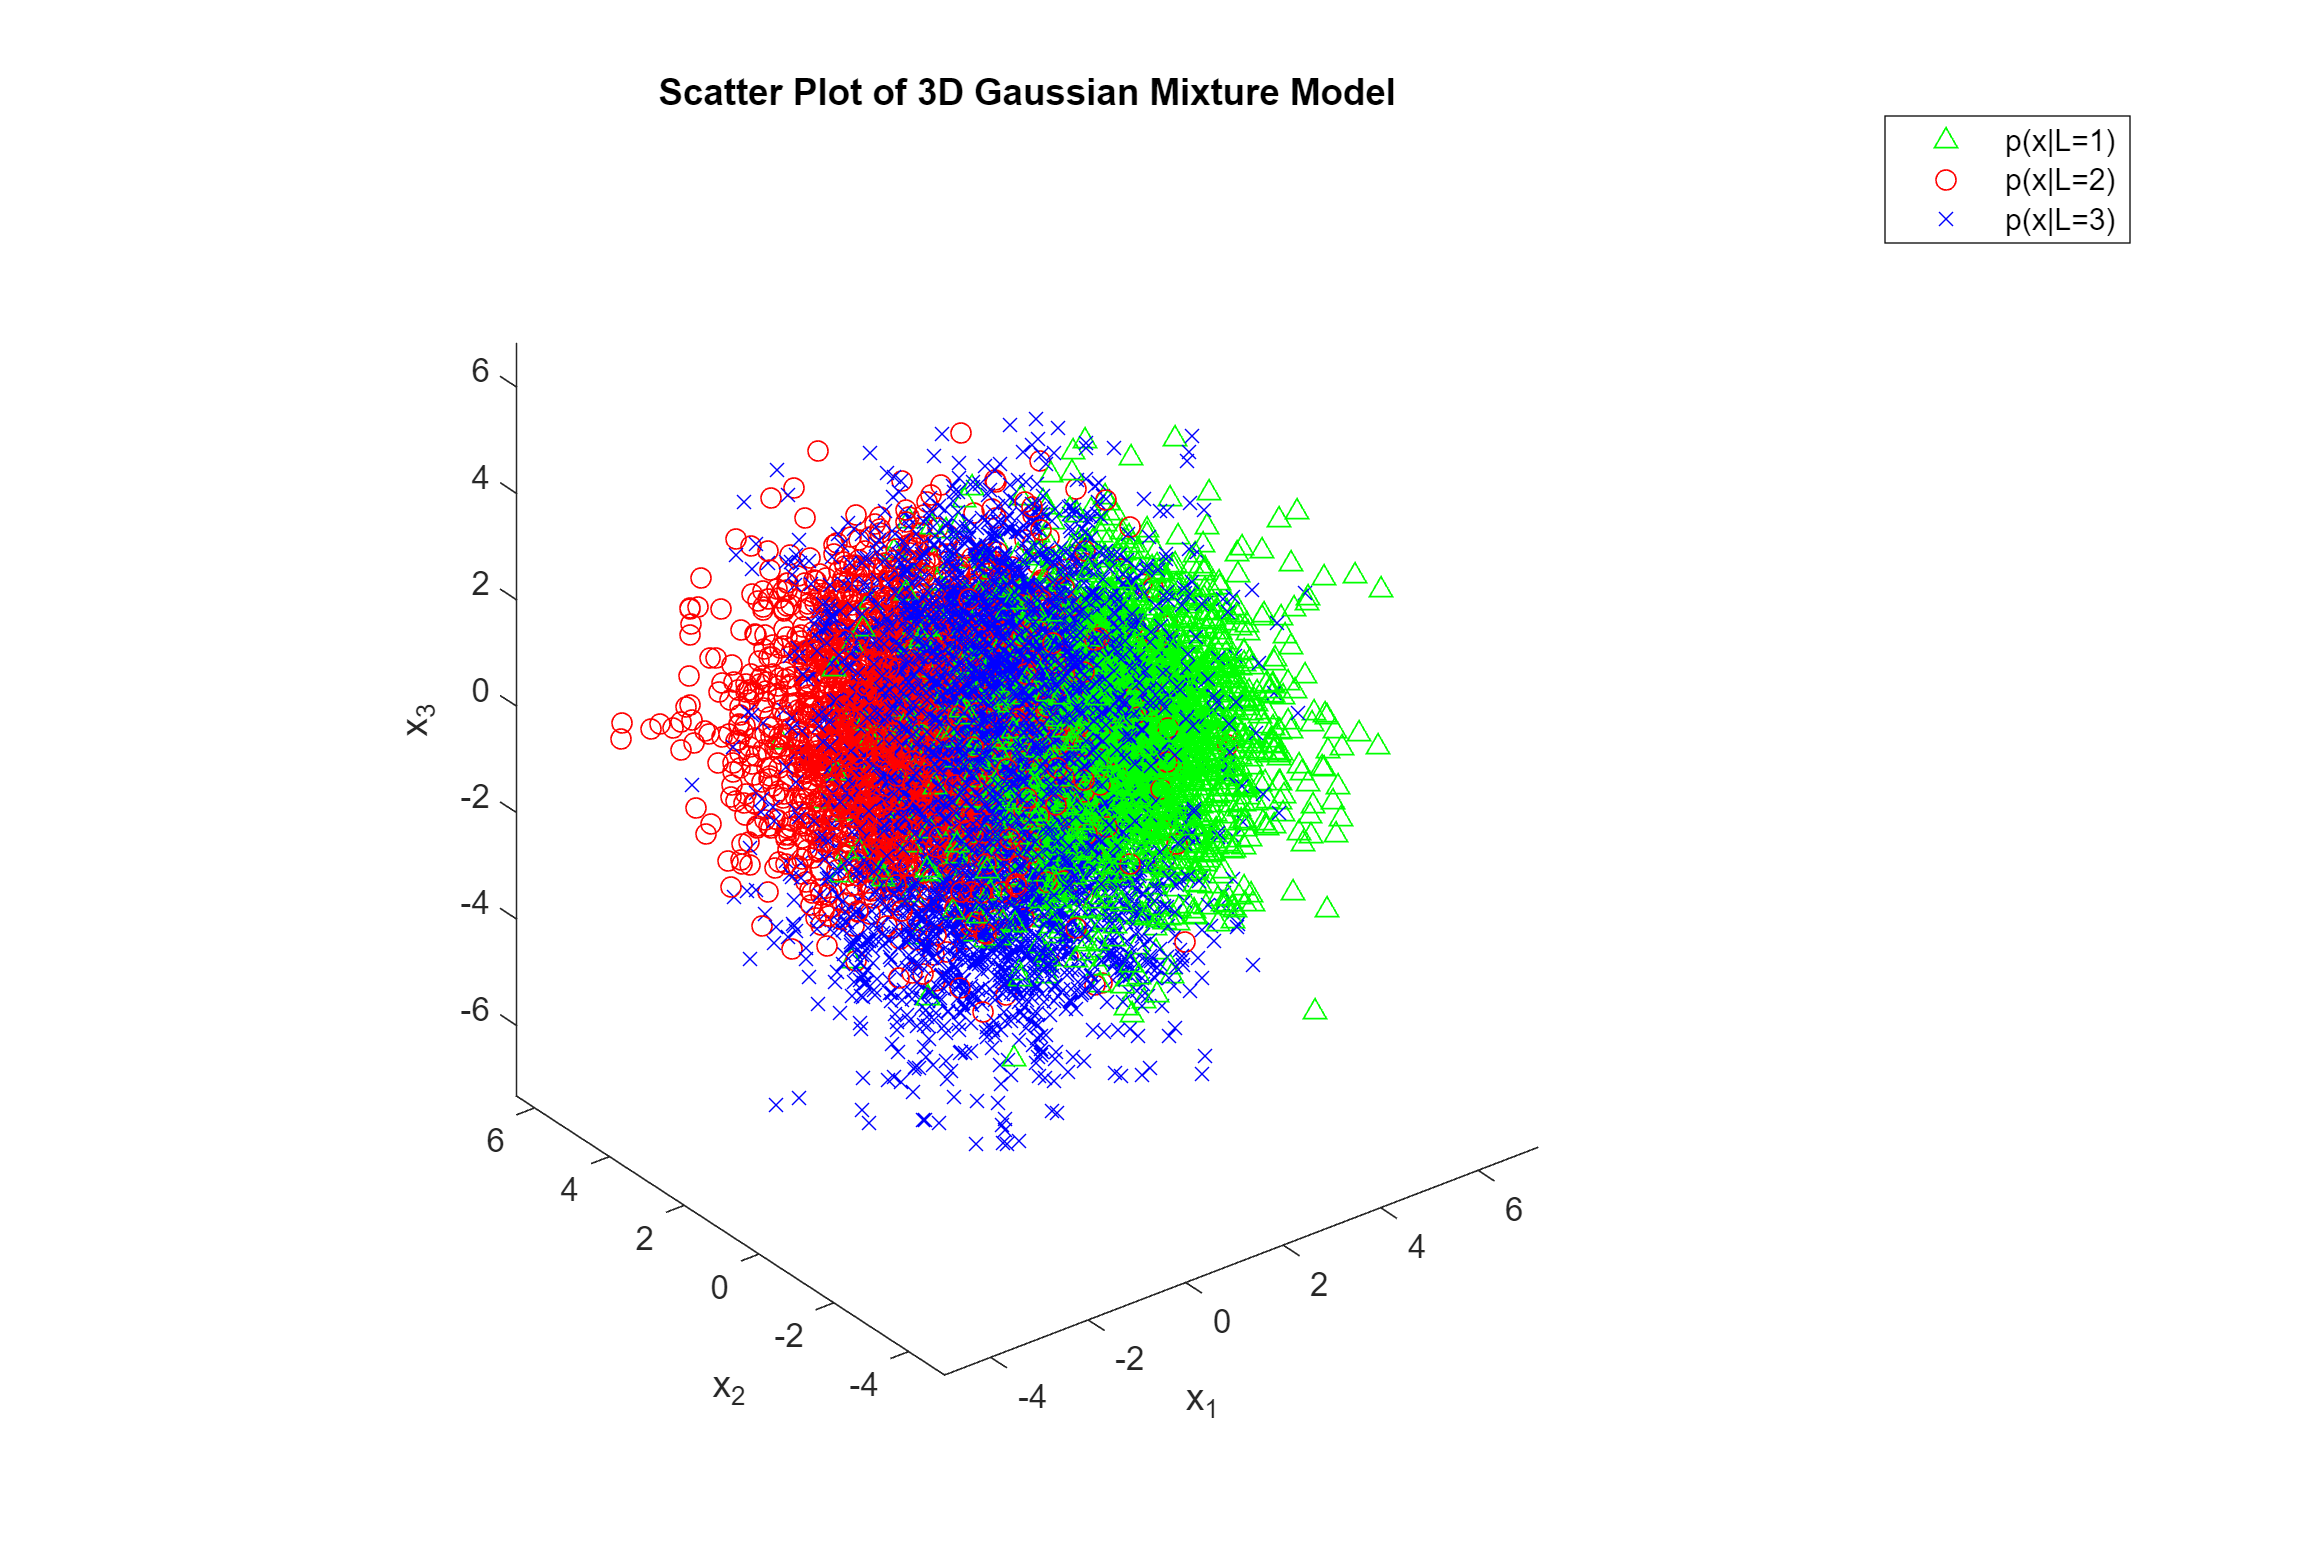

clear all, close all
% Generate 10,000 samples of a 3D Gaussian Mixed Model using Parameters
N = 10000; % # of samples to generate
C = 3; % # of classes
% Gaussian Mixture Model specifications
m1  = [2 0 0]';    C1 =  2*eye(3);
m2  = [0 2 0]';    C2 =  2*eye(3);
m31 = [0 0 -2]';   C31 = 2*eye(3);
m32 = [0 0 2]';    C32 = 2*eye(3);
w1  = 1/2; w2 = 1/2;
PL1 = 0.3; PL2  = 0.3; PL3 = 0.4;
% Create Struct that will store all Parameters specified and pass to
% generation function
gaussParameters.component4label  = [1,2,3,3]; % Vector indicating # of components for each class
gaussParameters.priors = [PL1,PL2,PL3];
gaussParameters.componentWeights = [w1, w2];
gaussParameters.meanVectors = [m1,m2,m31,m32];
covar(:,:,1) = C1;  covar(:,:,2) = C2;
covar(:,:,3) = C31; covar(:,:,4) = C32;
gaussParameters.covarMatrices = covar;
[data,classLabels] = HW2gmmData3D(N,gaussParameters); pause(1)

index1 = find(classLabels == 1); numL1samples = length(index1);
index2 = find(classLabels == 2); numL2samples = length(index2);
index3 = find(classLabels == 3); numL3samples = length(index3);
numLabels = [numL1samples, numL2samples, numL3samples];
% Compute empirical class Priors from random samples of GMM
P_l1 = numL1samples/N; P_l2 = numL2samples/N; P_l3 = numL3samples/N;
% Determine ERM decisions for each samples using specified (true) data PDF
gmmPriors = [0.3,0.3,0.2,0.2];
% Use gmdistribution function to generate cell arrays of GMM parameters and
% Class-Conditional pdfs
for l = 1:C
    components{l} = find(gaussParameters.component4label==l);
    classPriors(l,1) = sum(gmmPriors(components{l}));
    compPriors = gmmPriors(components{l})/classPriors(l,1);
    compMeans = gaussParameters.meanVectors(:,components{l})';
    compCovariance = gaussParameters.covarMatrices(:,:,components{l});
    classConditionalPDF{l} = gmdistribution(compMeans,compCovariance,compPriors);
end
% Show Cell array that displays # of Gaussian components for each class
components

components = 1×3 cell array
    {[1]}    {[2]}    {[3 4]}


% Compute class-conditional pdfs p(x|L=j) for j in {1,2,3}
classConditionalLikelihoods(1,:) = pdf(classConditionalPDF{1},data'); % p(x|L=1)
classConditionalLikelihoods(2,:) = pdf(classConditionalPDF{2},data'); % p(x|L=2)
classConditionalLikelihoods(3,:) = pdf(classConditionalPDF{3},data'); % p(x|L=3)
% Derive loss matrix Lambda
Lambda = [0,1,1;1,0,1;1,1,0]

Lambda =      0     1     1
     1     0     1
     1     1     0


% Derive diagonal matrix of class Priors
classPriorsMatrix = diag([P_l1, P_l2, P_l3])

classPriorsMatrix =     0.3078         0         0
         0    0.2962         0
         0         0    0.3960


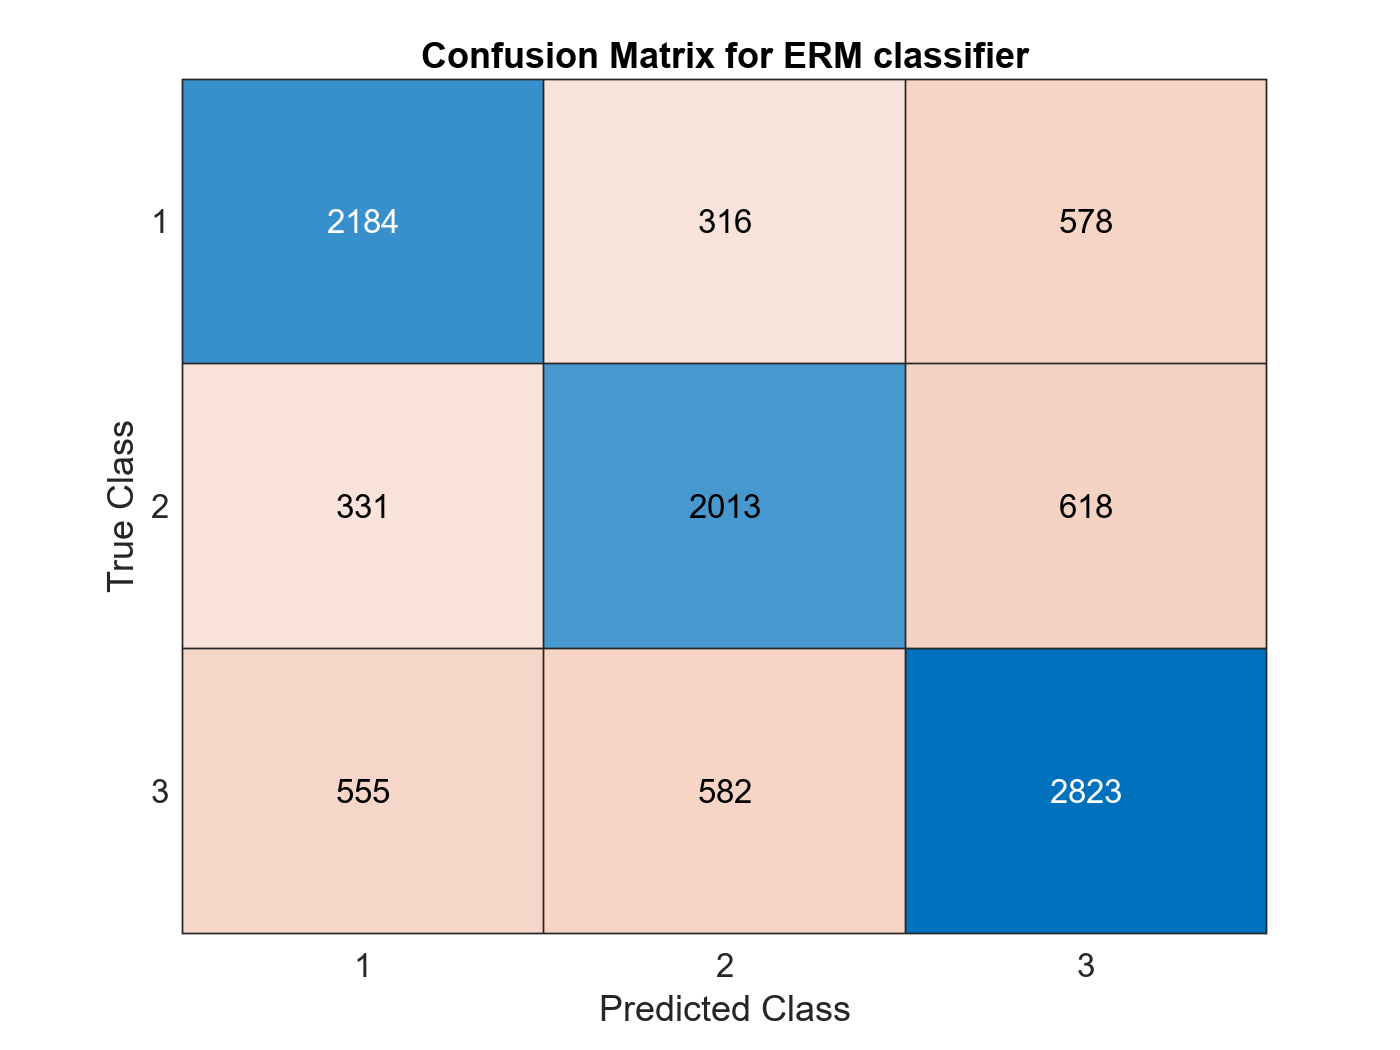

% Calculate the class Posterior Matrix which results from dot product of
% diagonal Priors and column vector of class-conditonal pdfs resulting in
% 3x10000 matrix
classPosteriors = classPriorsMatrix*classConditionalLikelihoods;
% Find min P(error) by finding argmin of the riskMatrix = Lambda.dot(classPosteriors)
riskMatrix = Lambda*classPosteriors;
[~,ERMdecision] = min(riskMatrix,[],1);
ConfMat = confusionmat(classLabels',ERMdecision');
figure(), confusionchart(ConfMat), title('Confusion Matrix for ERM classifier')

numTruePositive = sum(diag(ConfMat))

numTruePositive = 7020

Perror_empirical = 1 - numTruePositive/N 

Perror_empirical = 0.2980

After counting the correct number of classified samples, I calculated that the Empirical Minimum $P\left(\textrm{error}\right)=0\ldotp 298$ for the ERM classifier.

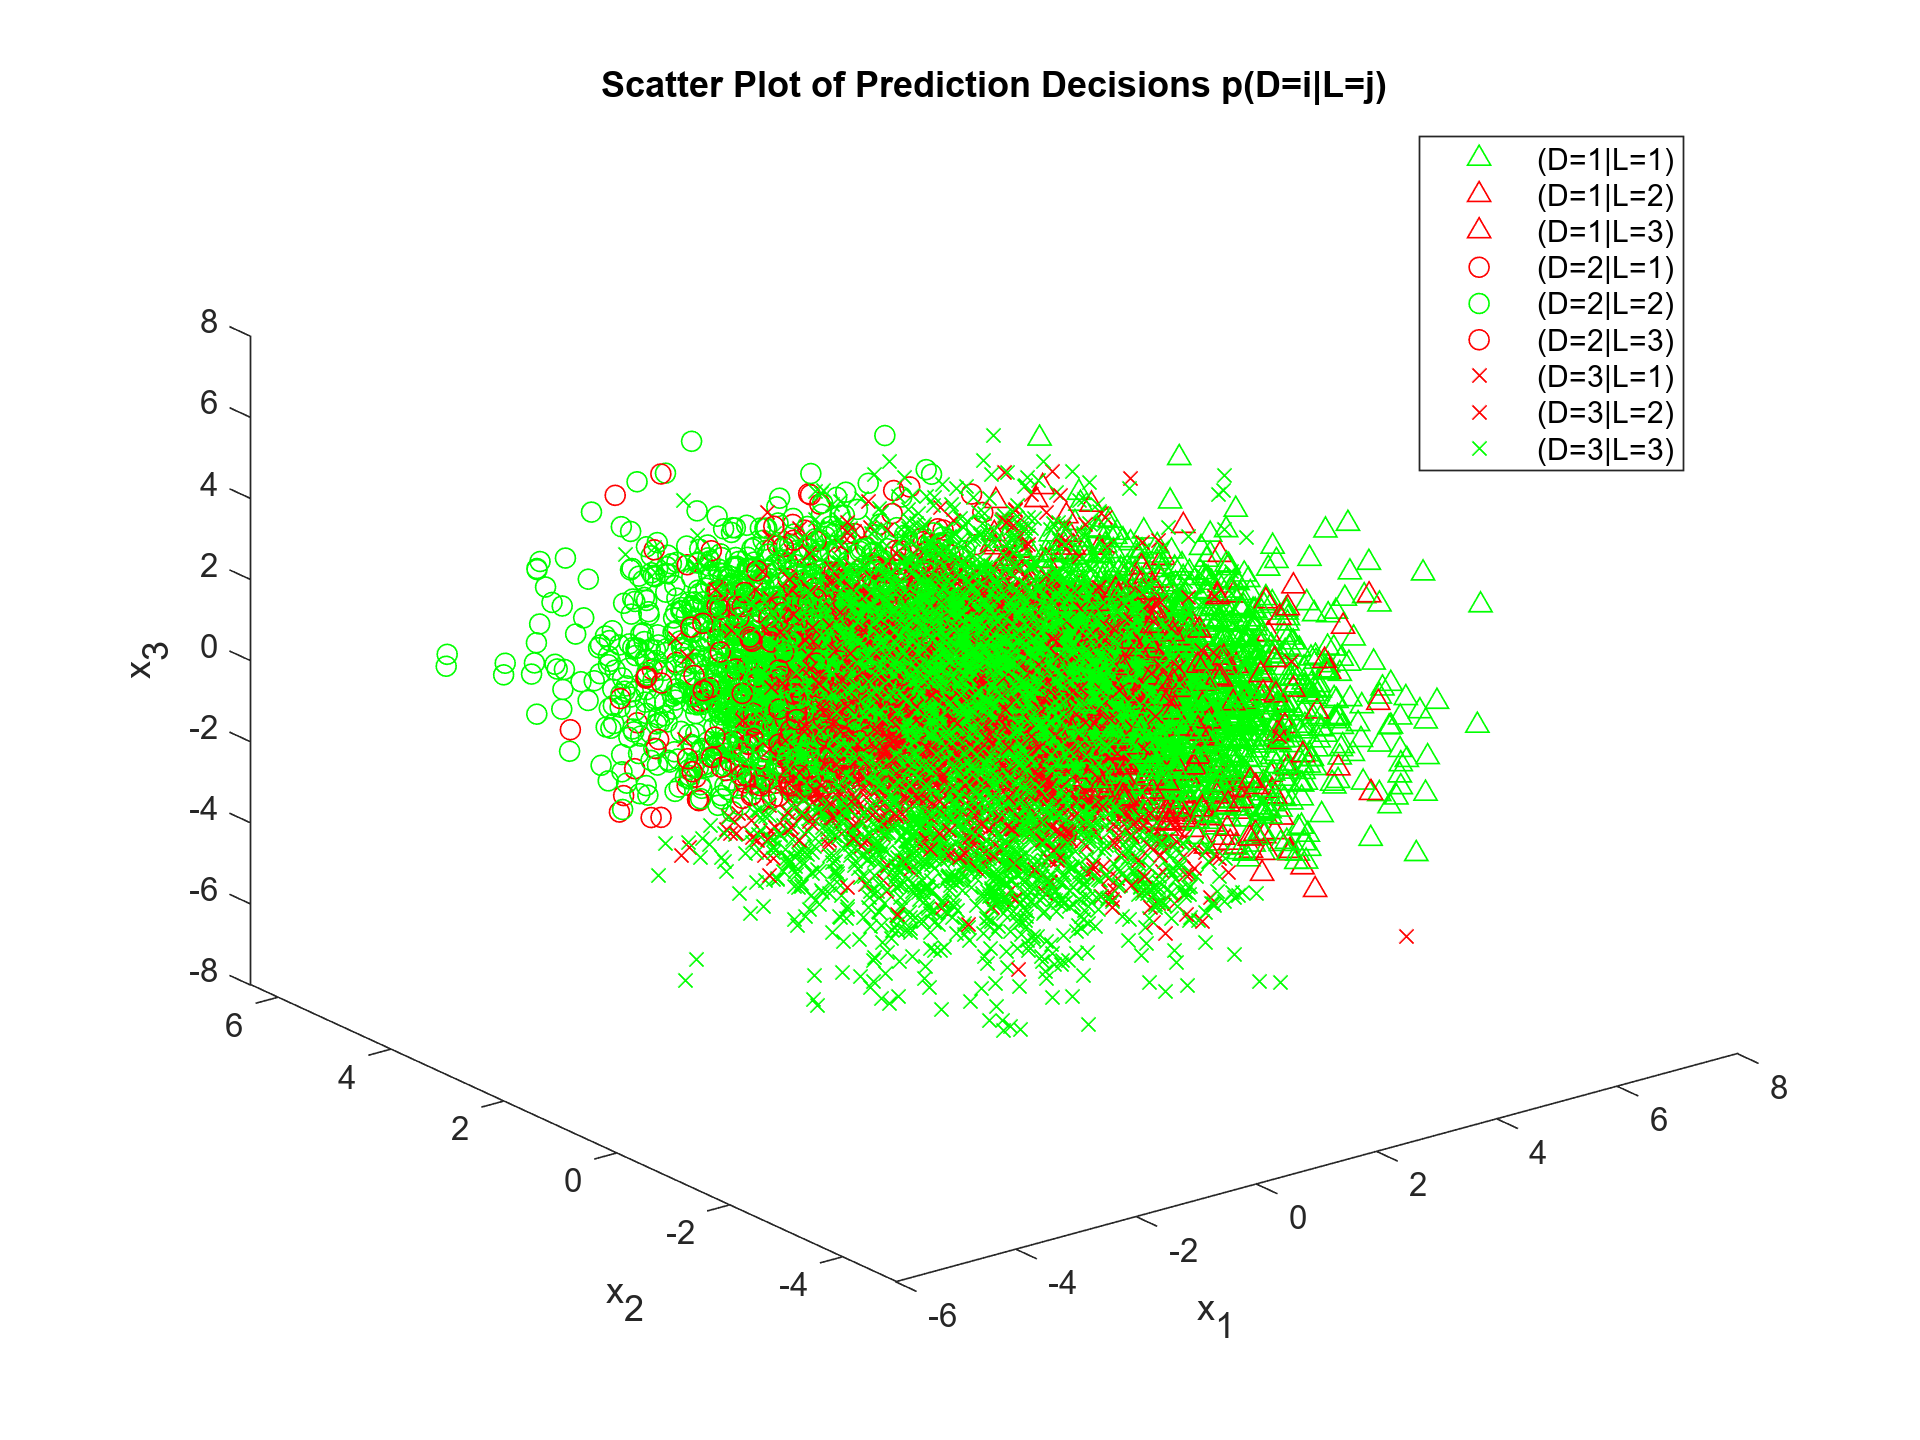

% Provide Visualization of prediction decisions P(D = i|L = j)
% if i == j -> plot in green with decision marker
% if i ~= j -> plot in red with same decision marker
% Should have 3 different marker shapes {triangle, circle, cross}
plotOptions.Marker = '^ox';
figure('Units','inches','Position',[0 0 8 6])
D = 3; % # of decisions
L = 3; % # of class Labels
for i = 1:D % predicition decision loop
    for j = 1:L % true class label loop
        % Find indices for all cases
        idx = find(ERMdecision==i & classLabels==j);
        if i == j
            % Plot correct predicitions in green
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[0 1 0]), hold on,
        else
            % Plot incorrect predicitions in red
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[1 0 0])
        end
    end
end
xlabel('x_1'), ylabel('x_2'), zlabel('x_3'), title('Scatter Plot of Prediction Decisions p(D=i|L=j)')
legend('(D=1|L=1)','(D=1|L=2)','(D=1|L=3)','(D=2|L=1)','(D=2|L=2)','(D=2|L=3)','(D=3|L=1)','(D=3|L=2)','(D=3|L=3)','Location', ...
    'best')

        **Part B: **Repeat the exercise for the ERM classification rule with the following loss matrices which respectively care 10 times or 100 times more about not making mistakes when $L=3:$

$\Lambda_{10} =\left\lbrack \begin{array}{ccc}
0 & 1 & 10\\
1 & 0 & 10\\
1 & 1 & 0
\end{array}\right\rbrack$ and $\Lambda_{100} =\left\lbrack \begin{array}{ccc}
0 & 1 & 100\\
1 & 0 & 100\\
1 & 1 & 0
\end{array}\right\rbrack$

        Note that, the ${\left(i,j\right)}^{\textrm{th}}$ entry of the loss matrix indicates the loss incurred by deciding on class $i$ when the true label is $j$. For this part, using the 10,000 samples, estimate the minimum expected risk that this optimal ERM classification rule will achieve. Present your results with visual and numerical reprentations. Briefly discuss interesting insights, if any 

% Repeat previous steps using loss matrix Lambda10
Lambda10 = [0,1,10;1,0,10;1,1,0]

Lambda10 =      0     1    10
     1     0    10
     1     1     0


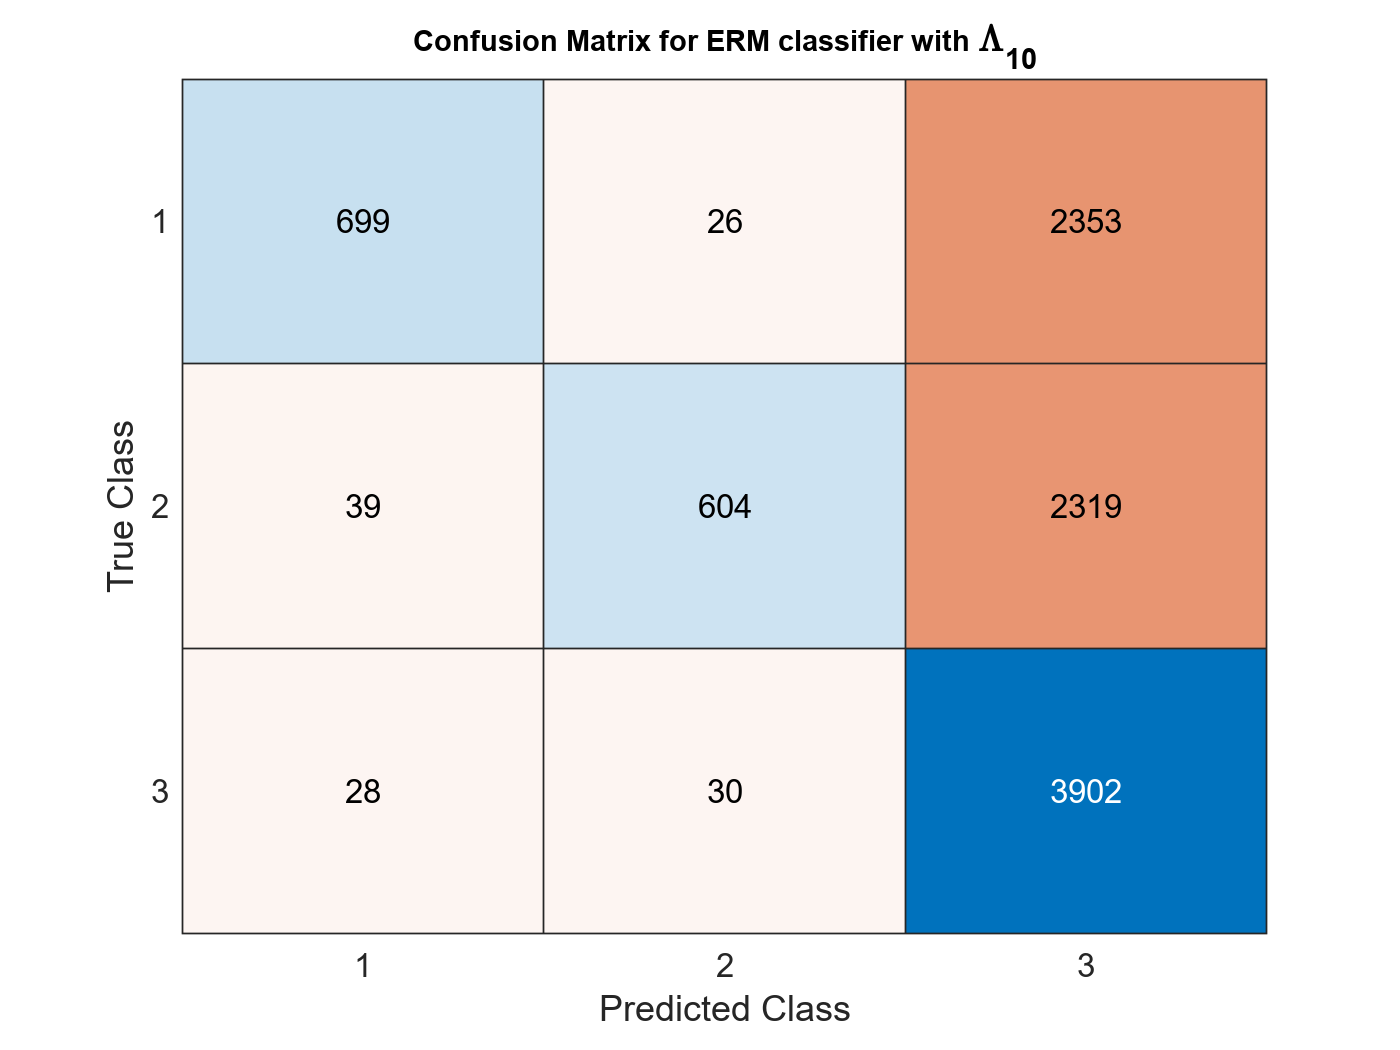

% Find min P(error) by finding argmin of the riskMatrix = Lambda10.dot(classPosteriors)
riskMatrix10 = Lambda10*classPosteriors;
[~,ERMdecision10] = min(riskMatrix10,[],1);
ConfMat10 = confusionmat(classLabels',ERMdecision10');
figure(), confusionchart(ConfMat10), title('Confusion Matrix for ERM classifier with \Lambda_{10}')

numTruePositive_L10 = sum(diag(ConfMat10))

numTruePositive_L10 = 5205

Perror_empirical_L10 = 1 - numTruePositive_L10/N 

Perror_empirical_L10 = 0.4795

After counting the correct number of classified samples, I calculated that the Empirical Minimum $P\left(\textrm{error}\right)=0\ldotp 4795$ when using the loss value matrix $\Lambda_{10}$

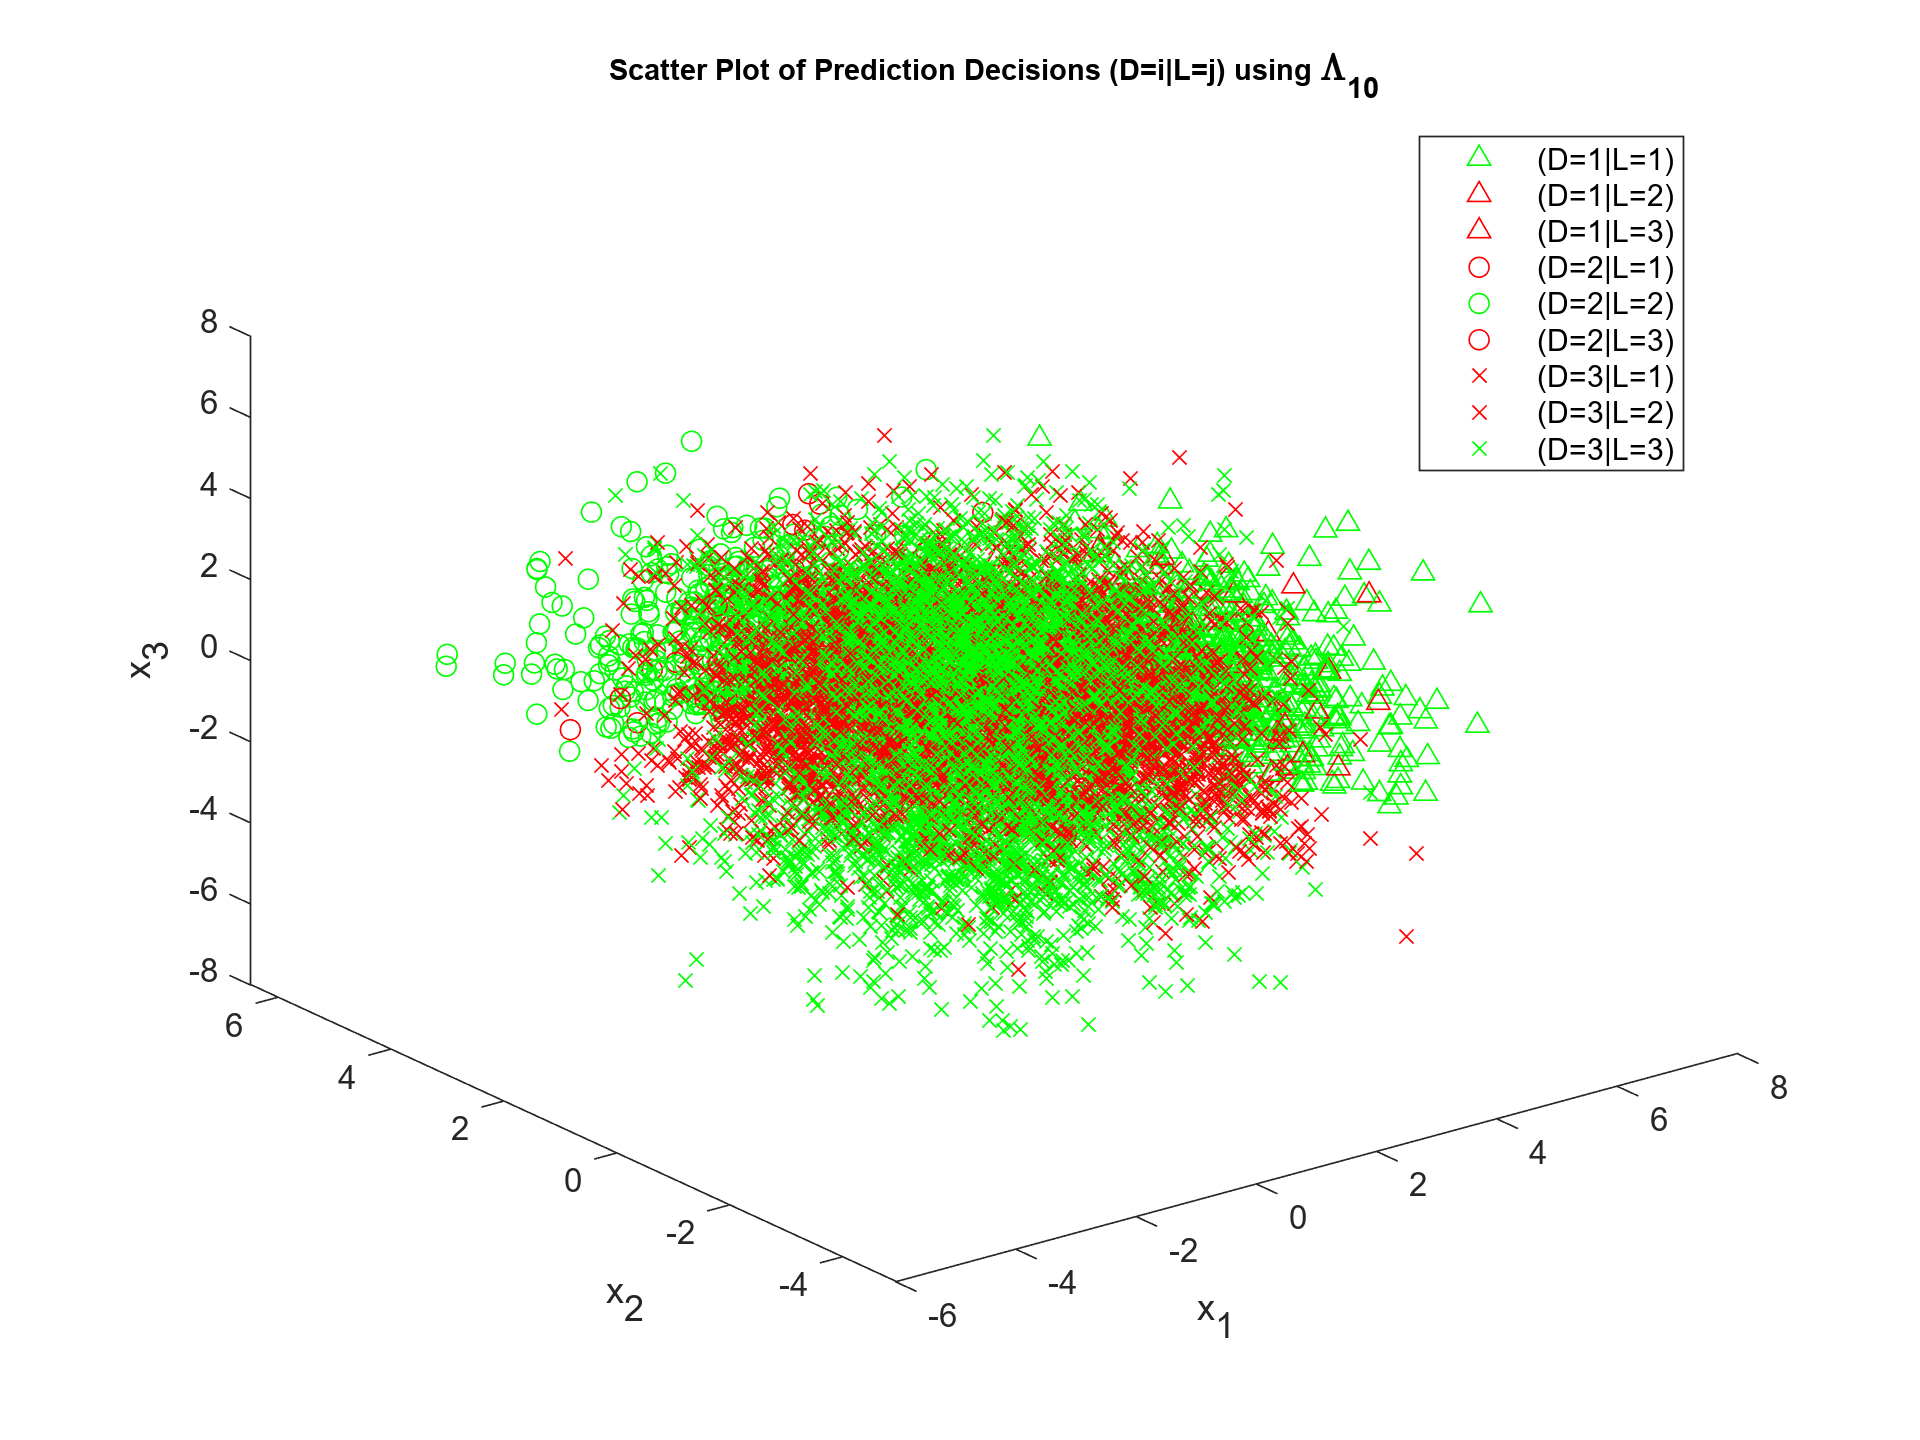

% Provide Visualization of prediction decisions P(D = i|L = j)
% if i == j -> plot in green with decision marker
% if i ~= j -> plot in red with same decision marker
% Should have 3 different marker shapes {triangle, circle, cross}
plotOptions.Marker = '^ox';
figure('Units','inches','Position',[0 0 8 6])
for i = 1:D % predicition decision loop
    for j = 1:L % true class label loop
        % Find indices for all cases
        idx = find(ERMdecision10==i & classLabels==j);
        if i == j
            % Plot correct predicitions in green
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[0 1 0]), hold on,
        else
            % Plot incorrect predicitions in red
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[1 0 0])
        end
    end
end
xlabel('x_1'), ylabel('x_2'), zlabel('x_3'), title('Scatter Plot of Prediction Decisions (D=i|L=j) using \Lambda_{10}')
legend('(D=1|L=1)','(D=1|L=2)','(D=1|L=3)','(D=2|L=1)','(D=2|L=2)','(D=2|L=3)','(D=3|L=1)','(D=3|L=2)','(D=3|L=3)','Location', ...
    'best'), hold off

% Repeat previous steps using loss matrix Lambda100
Lambda100 = [0,1,100;1,0,100;1,1,0]

Lambda100 =      0     1   100
     1     0   100
     1     1     0


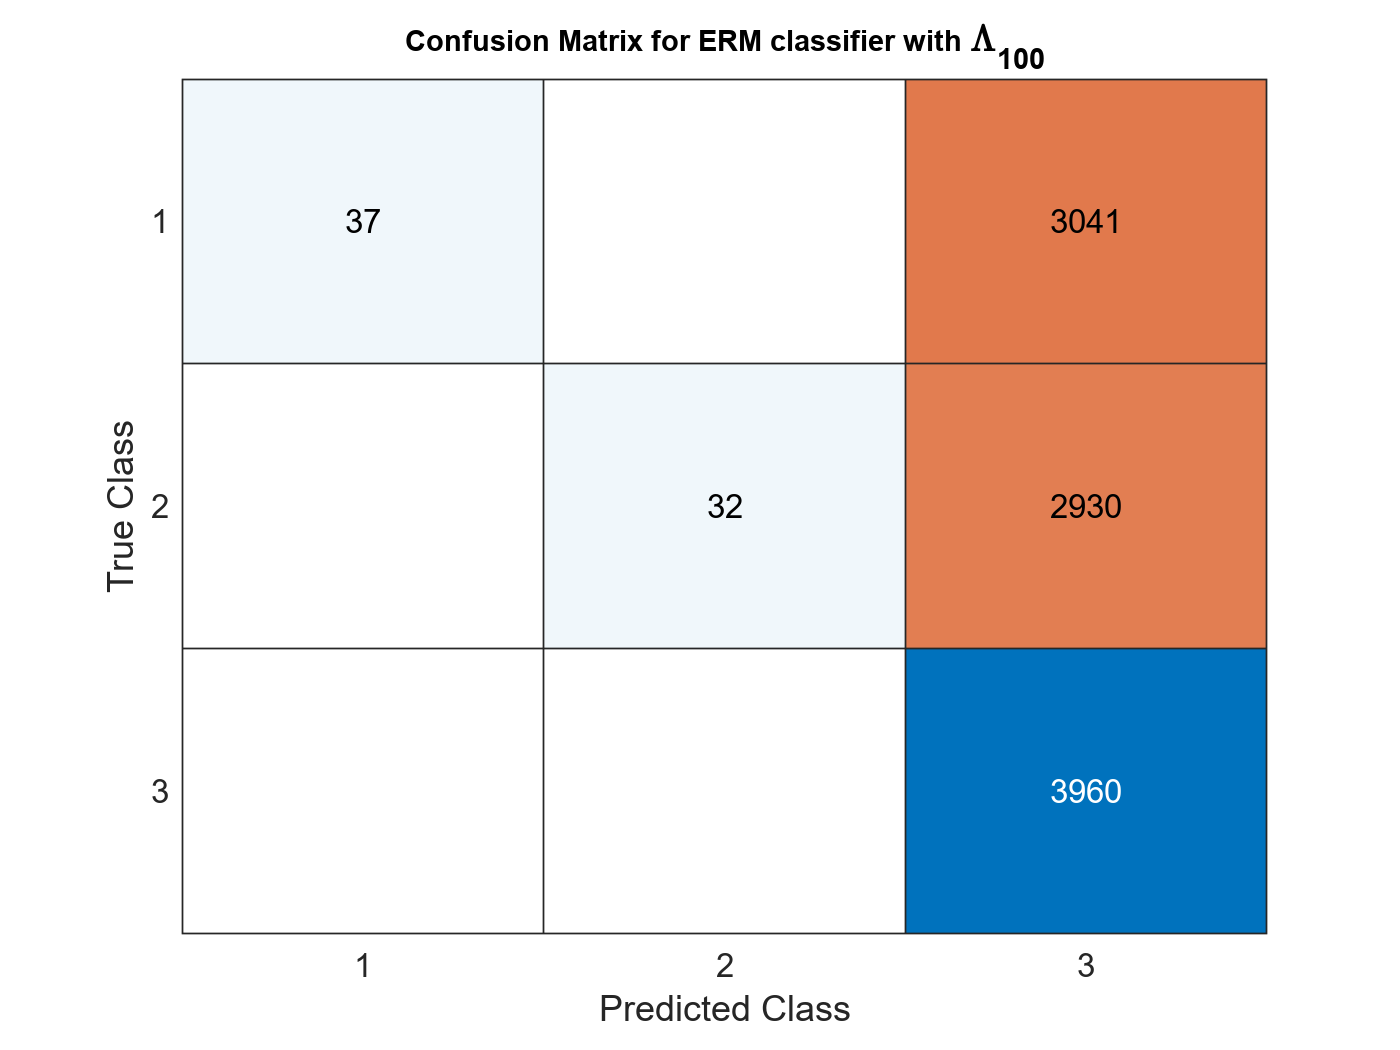

% Find min P(error) by finding argmin of the riskMatrix = Lambda100.dot(classPosteriors)
riskMatrix100 = Lambda100*classPosteriors;
[~,ERMdecision100] = min(riskMatrix100,[],1);
ConfMat100 = confusionmat(classLabels',ERMdecision100');
figure(), confusionchart(ConfMat100), title('Confusion Matrix for ERM classifier with \Lambda_{100}')

numTruePositive_L100 = sum(diag(ConfMat100))

numTruePositive_L100 = 4029

Perror_empirical_L100 = 1 - numTruePositive_L100/N 

Perror_empirical_L100 = 0.5971

After counting the correct number of classified samples, I calculated that the Empirical Minimum $P\left(\textrm{error}\right)=0\ldotp 5971$ when using the loss value matrix $\Lambda_{100}$

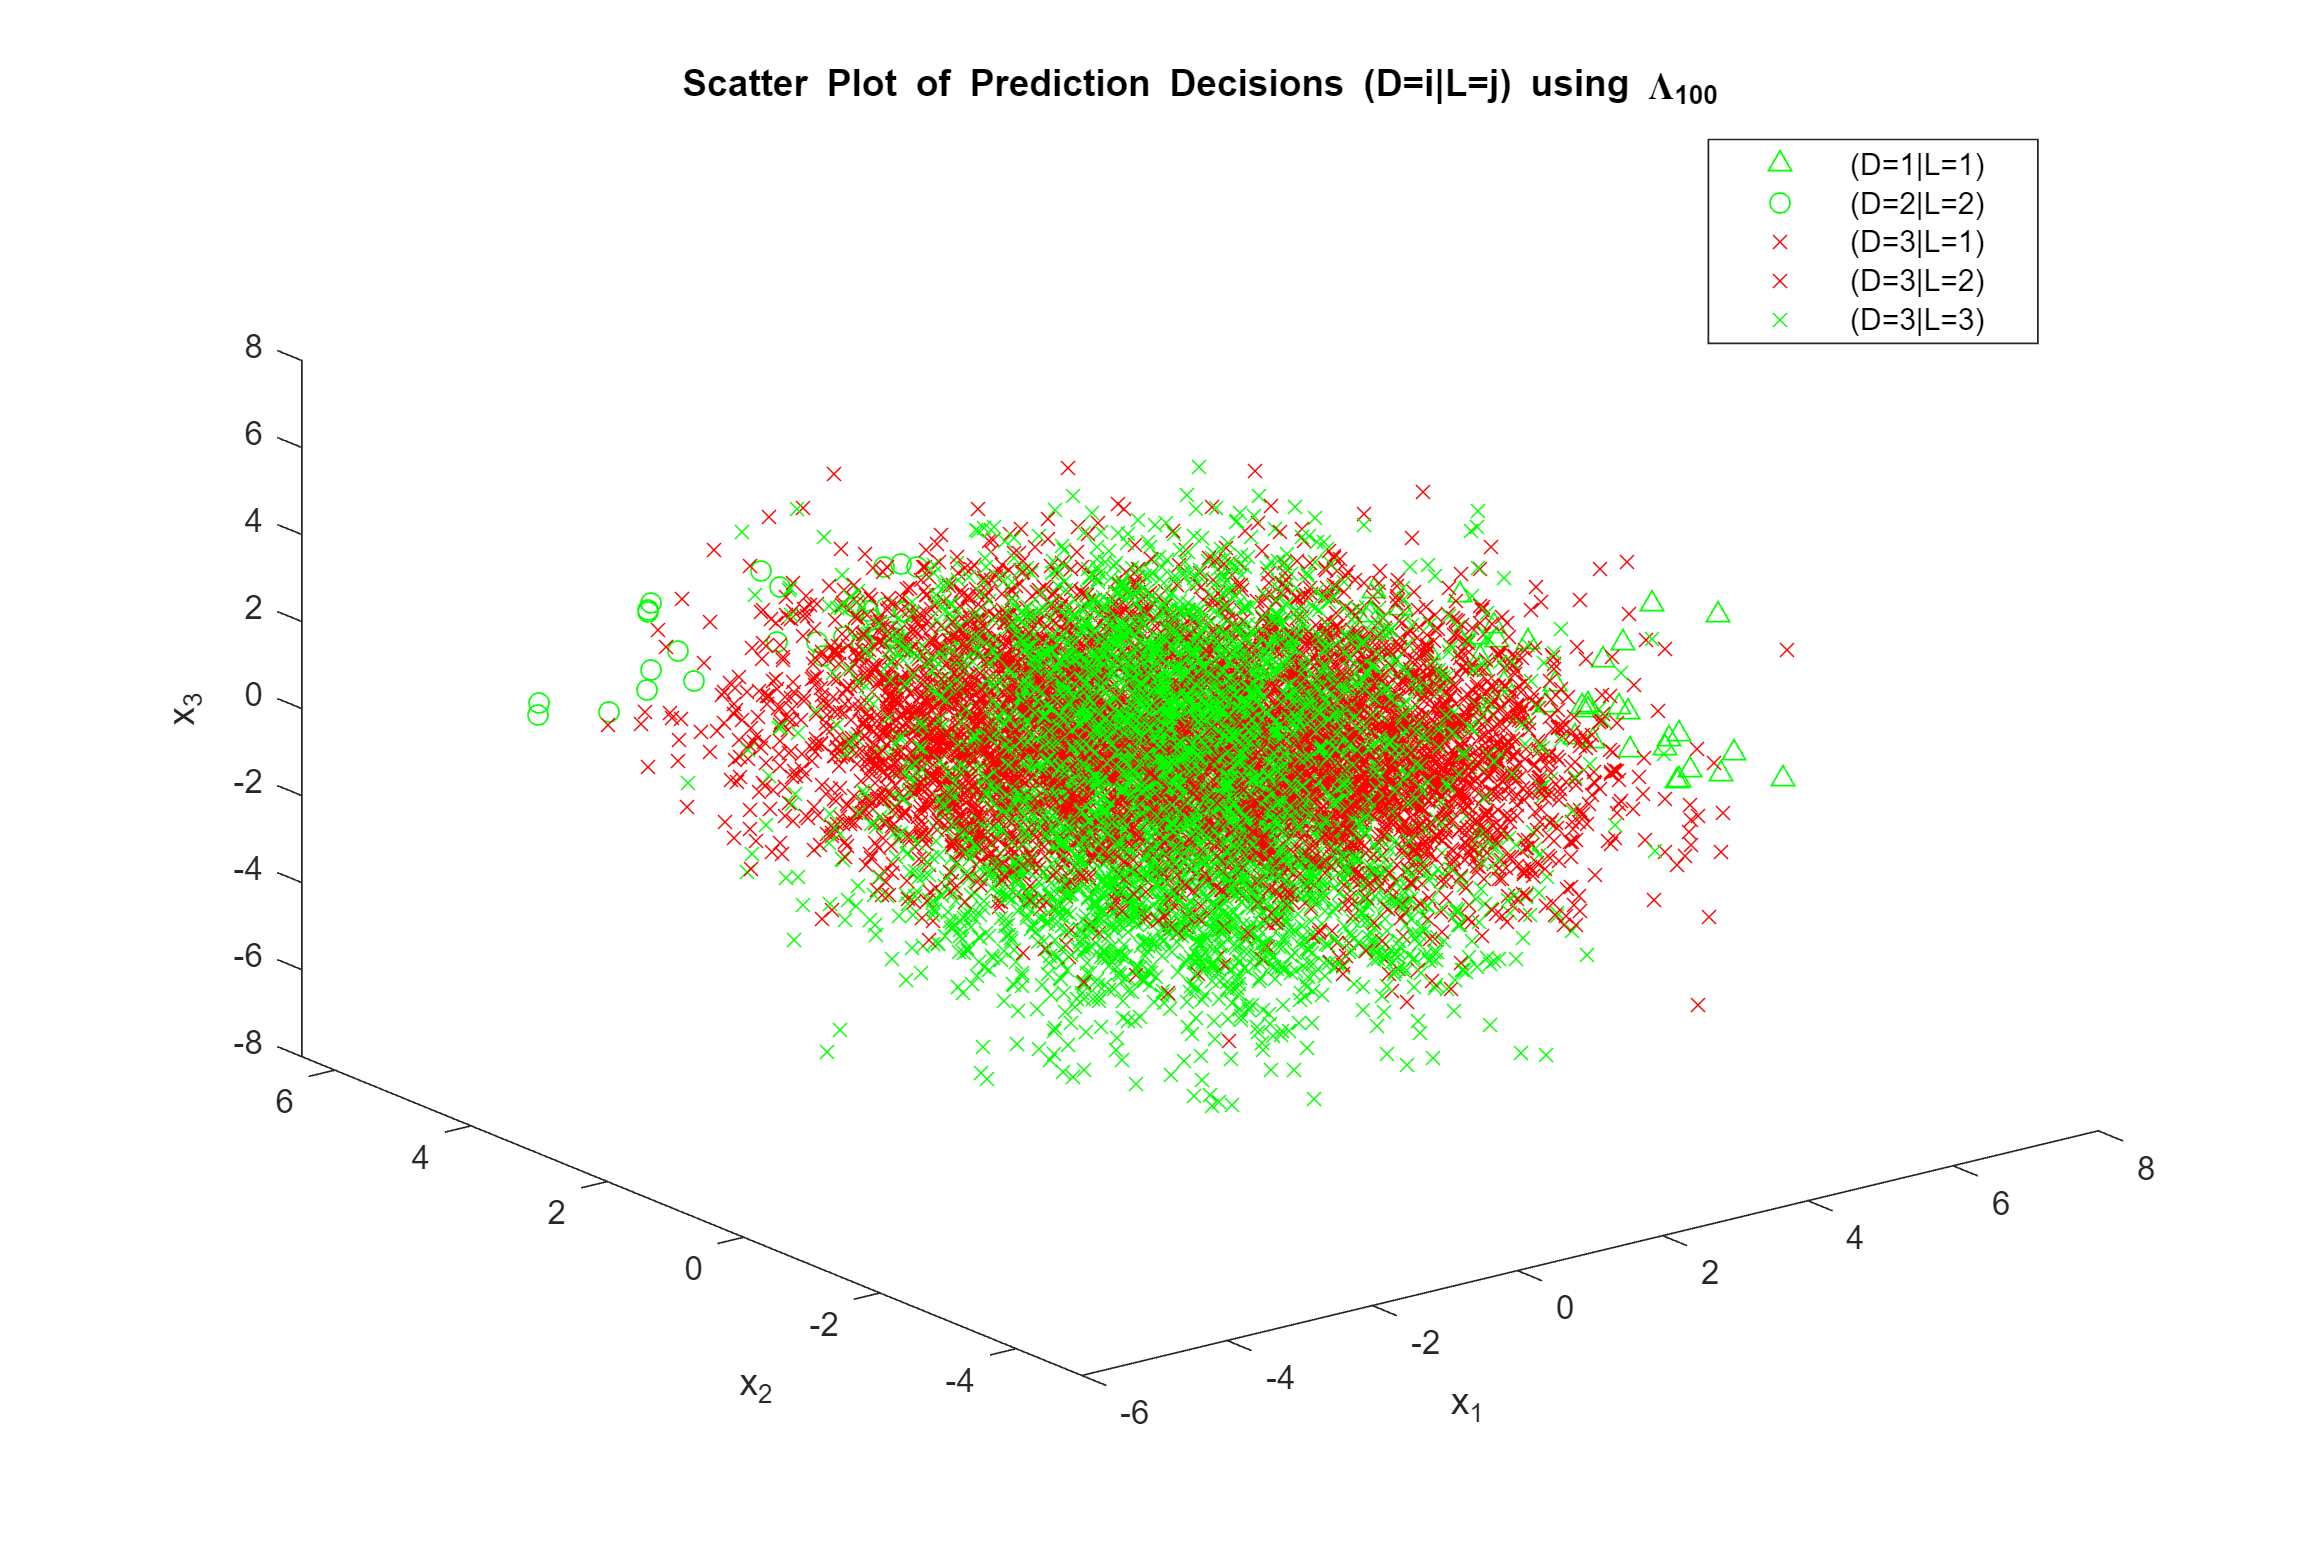

% Provide Visualization of prediction decisions P(D = i|L = j)
% if i == j -> plot in green with decision marker
% if i ~= j -> plot in red with same decision marker
% Should have 3 different marker shapes {triangle, circle, cross}
plotOptions.Marker = '^ox';
figure('Units','inches','Position',[0 0 8 6])
for i = 1:D % predicition decision loop
    for j = 1:L % true class label loop
        % Find indices for all cases
        idx = find(ERMdecision100==i & classLabels==j);
        if i == j
            % Plot correct predicitions in green
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[0 1 0]), hold on,
        else
            % Plot incorrect predicitions in red
            plot3(data(1,idx),data(2,idx),data(3,idx),plotOptions.Marker(i),'Color',[1 0 0])
        end
    end
end
xlabel('x_1'), ylabel('x_2'), zlabel('x_3'), title('Scatter Plot of Prediction Decisions (D=i|L=j) using \Lambda_{100}')
legend('(D=1|L=1)','(D=2|L=2)','(D=3|L=1)','(D=3|L=2)','(D=3|L=3)','Location','best'), hold off

Above shows the scatter plot of correct and incorrect predictions. With the loss matrix having loss values for $L=3$ being 100 times larger than the other misclassification values, the ERM classifier came to the decision $D=3$ more often because of the large cost associated with prediciting a sample incorrectly. This resulted in a confusion matrix that only contains True Positives along the diagonal of the confusion matrix, and all other predicitions were considered to be class 3. These values are then represented in the above scatter plot of decision markers and true/false labels, where only 5 predicition components were possible due to the high cost for predicting class 3 incorrectly. 

## Function Code for Question 1:

function [data,classLabels] = HW2gmmData2D(N,Parameters)
% N = # of samples to generate
% Returns data and class labels
% Determine dimensions of data from parameters
%
rng(7);
% Gaussian Mixture Model Specifications
classPriors = Parameters.priors; % Class Priors
numClasses = length(classPriors);     % # of classes
component4label = Parameters.component4label; % Vector stating # of components for each class
% Count how many components for each class there are
for i = 0:numClasses-1
    numComponent4eachClass(i+1) = sum(component4label == i);
end
componentWeights = Parameters.componentWeights; % Component weights for mixed gaussians
numComponents = length(componentWeights); % # of components for mixed gaussians
meanVectors = Parameters.meanVectors; % Mean vectors for all gaussians
covarMatrices = Parameters.covarMatrices; % Covariance matrices for all gaussians
d = size(meanVectors,1); % Dimension determined from size of columns in mean vectors
data = zeros(d,N); % Zero-pad the data vector to d-dimension x N-samples
classLabels = (rand(1,N) >= classPriors(1)); % Create random-valued vector from 0 to 1 and check whether values are >= P(L=0)
for i = 0:numClasses-1 % For loop for class labels 0 and 1
    idx = find(classLabels==i); % logical array that finds indices of classes 0 and 1
    if i == 0 % class 0 - contains 2 Gaussians components
        n0 = length(idx); % # of Class 0 samples to generate
        mixedParameters.priors = componentWeights; % weights of gaussian components
        mixedParameters.meanVectors = meanVectors(:,1:numComponents); % component means
        mixedParameters.covarMatrices = covarMatrices(:,:,1:numComponents); % component covariance matrices
        [data(:,idx),gaussComponents] = GaussMixModel(n0,mixedParameters);  % generate mixed gaussian into data vector at indices of class 0
        plot(data(1,idx(gaussComponents==1)),data(2,idx(gaussComponents==1)),'rsquare'), hold on, 
        plot(data(1,idx(gaussComponents==2)),data(2,idx(gaussComponents==2)),'rsquare'), hold on,
    elseif i == 1 % class 1 - contains 1 single gaussian component
        n1 = length(idx); % # of Class 1 samples to generate
        m1 = meanVectors(:,3)'; % mean vector for class 1
        C1 = covarMatrices(:,:,3);
        data(:,idx) = mvnrnd(m1,C1,n1)';
        plot(data(1,idx),data(2,idx),'bo'), hold on,
        axis equal, xlabel('x_1'), ylabel('x_2'), 
        legend('p(x|L=0)', '','p(x|L=1)'),
        xticks(-5:1:9), yticks(-5:1:9)
        title('Scatter Plot of Gaussian Mixture Model'), hold off
    end
end
end

function [data,componentLabels] = GaussMixModel(N,Parameters)
% N = # of samples to generate
% Parameters contains mixed gaussian component parameters
priors = Parameters.priors; % Priors or weights for each component
mu = Parameters.meanVectors; % Mean vectors for each component
covarMatrix = Parameters.covarMatrices; % Covariances for each component
dim = size(mu,1); % Dimension determined from size of mean vectors
numGauss = length(priors); % # of gaussian components determined from length of weights
data = zeros(dim,N);    % Zero-pad data to d-dimensions x samples
componentLabels = zeros(1,N); % Zero-pad component labels to size of N
% Compute randomly which sample will be generated from each component
randSample = rand(1,N); t = [cumsum(priors)];
for i = 1:numGauss
    idx = find(randSample <= t(i)); % find which indices will be generated randomly for each component
    numSamples = length(idx); % # of samples to generate for component
    componentLabels(1,idx) = i*ones(1,numSamples); % Keep track of component labels
    randSample(1,idx) = 1.1*ones(1,numSamples); % these samples should not be used again
    data(:,idx) = mvnrnd(mu(:,i),covarMatrix(:,:,i),numSamples)'; % Generate component data at the random indice selected
end
end

## Function Code for Question 2:

function [data,classLabels] = HW2gmmData3D(N,Parameters)
% N = # of samples to generate
% Returns data and class labels
% Determine dimensions of data from parameters
%
rng(7);
% Gaussian Mixture Model Specifications
classPriors = Parameters.priors; % Class Priors
numClasses = length(classPriors); % # of classes
component4label = Parameters.component4label; % Vector stating # of components for each class
% Count how many components for each class there are
for i = 1:numClasses
    numComponent4eachClass(i) = sum(component4label == i);
end
componentWeights = Parameters.componentWeights; % Component weights for mixed gaussians
numComponents = length(componentWeights); % # of components for mixed gaussians
meanVectors = Parameters.meanVectors; % Mean vectors for all gaussians
covarMatrices = Parameters.covarMatrices; % Covariance matrices for all gaussians
d = size(meanVectors,1); % Dimension determined from size of columns in mean vectors
data = zeros(d,N); % Zero-pad the data vector to d-dimension x N-samples
classLabels = zeros(1,N); % Zero-pad class labels
randSample = rand(1,N); % random vector to decide # of samples 
t = [cumsum(classPriors),1]; % threshold values based on class priotrs for random sample generation
figure('Units','inches','Position',[0 0 12 8])
for i = 1:numClasses % For loop for class sample generation
    classIndex = find(randSample <= t(i));
    idx_len = length(classIndex); % # of samples randomly choosen for class
    classLabels(1,classIndex) = i*ones(1,idx_len); % store index values of class labels
    randSample(1,classIndex) = 1.1*ones(1,idx_len); % Assure choosen indices are not selected again
    if i == 1 % class 1 - contains 1 single gaussian component
        m1 = meanVectors(:,i)'; % mean vector for class 1
        C1 = covarMatrices(:,:,i); % covariance matrix for class 1
        data(:,classIndex) = mvnrnd(m1,C1,idx_len)';
        plot3(data(1,classIndex),data(2,classIndex),data(3,classIndex),'g^'), hold on,
    elseif i == 2 % class 2 - contains 1 single gaussian component
        m2 = meanVectors(:,i)'; % mean vector for class 1
        C2 = covarMatrices(:,:,i); % covariance matrix for class 1
        data(:,classIndex) = mvnrnd(m2,C2,idx_len)';
        plot3(data(1,classIndex),data(2,classIndex),data(3,classIndex),'ro'), hold on
    elseif i == 3 % class 3 - contains 2 Gaussians components
        mixedParameters.priors = componentWeights; % weights of gaussian components
        mixedParameters.meanVectors = meanVectors(:,i:i+1); % component means
        mixedParameters.covarMatrices = covarMatrices(:,:,i:i+1); % component covariance matrices
        [data(:,classIndex),gaussComponents] = GaussMixModel(idx_len,mixedParameters);  % generate mixed gaussian into data vector at indices of class 0
        plot3(data(1,classIndex(gaussComponents==1)),data(2,classIndex(gaussComponents==1)),data(3,classIndex(gaussComponents==1)),'bx'), hold on, 
        plot3(data(1,classIndex(gaussComponents==2)),data(2,classIndex(gaussComponents==2)),data(3,classIndex(gaussComponents==2)),'bx'), hold on,
        axis equal, xlabel('x_1'), ylabel('x_2'), zlabel('x_3') 
        legend('p(x|L=1)','p(x|L=2)','p(x|L=3)'),
        %xticks(-5:1:9), yticks(-5:1:9)
        title('Scatter Plot of 3D Gaussian Mixture Model'), hold off
    end
end
end